## Constants

clear; close all; clc;

%% --- Environment constants (from thesis Table 2.2.1) ---
rho0 = 1.225;      % kg/m^3
a0   = 340.429;    % m/s (speed of sound at ground)
Rearth = 6.356766e6; % m
Lat = deg2rad(45);   % latitude used in thesis
g0   = 9.80665*(1-0.0026*cos(2*Lat));    % m/s^2

%% --- Projectile parameters (155 mm from thesis Table 2.3.2) ---
D  = 0.155;            % caliber (m)
S  = 1.89e-2;          % reference area (m^2)
M  = 43.25;            % mass (kg)
Il = 0.15;             % longitudinal moment of inertia (kg m^2)
It = 1.61;             % transverse moment of inertia (kg m^2)

%% --- Example aerodynamic coefficient tables (Mach -> coefficients)
Mach_table = [0.0 0.8 1.0 1.2 2.0 3.0];
CD_table   = [0.30 0.28 0.46 0.38 0.30 0.28];   % placeholder
CL_table   = [0.5 1.8 1.5 1.7 2.0 1.8]; % placeholder
Cmagf_table= [0.00 -0.08 -0.12 -0.15 -0.13 -0.10]; % placeholder
Cmagm_table= [0.00  0.04  0.06  0.07  0.06  0.05]; % placeholder
CMq_table  = [-22 -20 -18 -15 -12 -10]; % placeholder
CMa_table  = [1.8 2.2 2.6 2.8 2.5 2.2]; % placeholder
Cspin_table= [-0.02 -0.03 -0.04 -0.05 -0.045 -0.040]; % placeholder

% interpolation helper
interpCoeff = @(tableMach, tableVals, Mach) interp1(tableMach, tableVals, Mach, 'linear', 'extrap');

%% --- Initial conditions ---
% Position (local frame L). Use NED-like: x-forward, y-right, z-down (here z is altitude negative)
x0 = 0; y0 = 0; h0 = 0;   % start at ground level (h = altitude)
z0 = -h0;                 % local z coordinate (thesis uses z negative down convention)
V0 = 800;                 % initial speed m/s (gun launch example)
elev = deg2rad(45);       % launch elevation
azim = deg2rad(0);        % azimuth
vx0 = V0 * cos(elev) * cos(azim);
vy0 = V0 * cos(elev) * sin(azim);
vz0 = -V0 * sin(elev);    % negative downwards if z down convention; we'll use consistent sign

% Attitude: use quaternion initial corresponding to yaw, pitch, roll
yaw0 = azim; pitch0 = elev; roll0 = 0;
q0 = eul2quat([yaw0, pitch0, roll0],'ZYX'); % MATLAB builtin: [yaw, pitch, roll]

% Angular rates in body (p,q,r) initial (spin + small transverse)
p0 = 1000; % spin rate rad/s (example — high spin)
q0_ang = 0; r0_ang = 0;

% Full state vector for ODE:
% state = [x; y; z; vx; vy; vz; q0; q1; q2; q3; p; q; r]
state0 = [x0; y0; z0; vx0; vy0; vz0; q0(:); p0; q0_ang; r0_ang];

## Run simulation

options = odeset('Events', @impact_event);

[t, X, te, Xe] = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), [0 200], state0, options);

%% --- Extract results ---
x = X(:,1); y = X(:,2); z = X(:,3);
vx = X(:,4); vy = X(:,5); vz = X(:,6);
quat = X(:,7:10);
p = X(:,11); q = X(:,12); r = X(:,13);

altitude = -z; % if z is negative down

%% --- Time span ---
T = te;
tspan = [0 T]; % seconds


## Plots

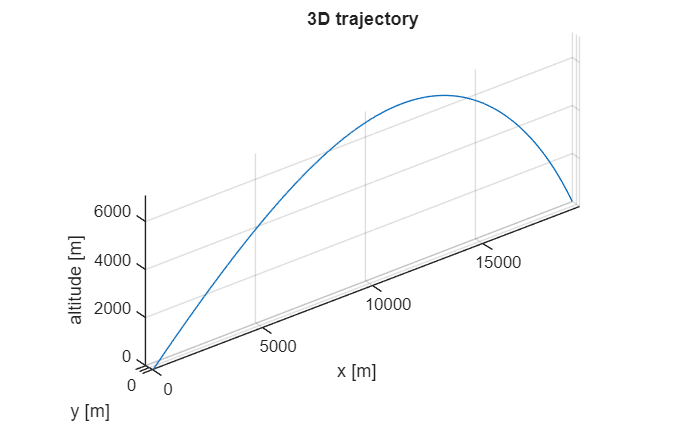

figure;
plot3(x, y, altitude); grid on; axis equal;
xlabel('x [m]'); ylabel('y [m]'); zlabel('altitude [m]');
title('3D trajectory');

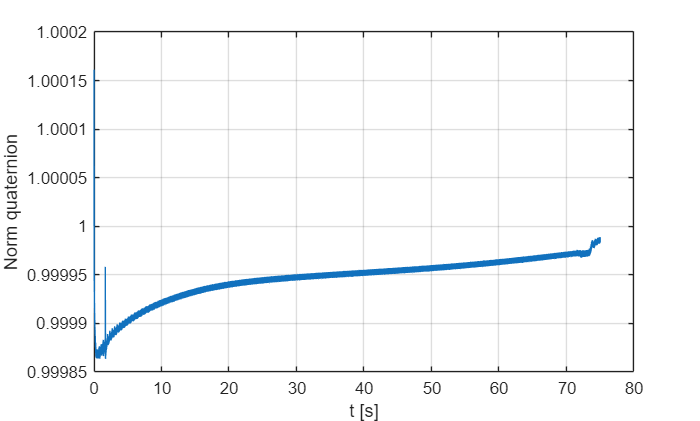

figure;
plot(t,sqrt(quat(:,1).^2+quat(:,2).^2+quat(:,3).^2+quat(:,4).^2));ylabel("Norm quaternion"); xlabel("t [s]");
grid on;

## Jacobian A(t) evaluation

N = 1000; % can be increased

t_table = linspace(0,T,N+1).';
sol = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), tspan, state0);
X_table = deval(sol, t_table).'; % row vector

n = size(X_table,2); % # states
A_table = zeros(n,n,N+1);


f_dyn = @(x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff);

for k = 1:N+1
    xk = X_table(k,:).';
    A_table(:,:,k) = compute_A_numeric(xk, f_dyn);
end

## Stability analysis

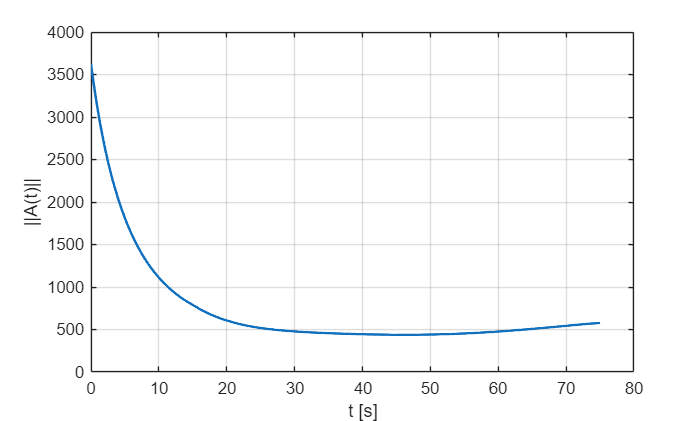

Nt = length(t_table);

A_norm = zeros(Nt,1);
real_part = zeros(n,Nt);

for k = 1:Nt
    %Ak = A_of_t(t_table(k),t_table,A_table); % unnecessary
    Ak = A_table(:,:,k);
    A_norm(k) = norm(Ak,2); 
    s = eig(Ak);
    real_part(:,k) = real(s);
end

figure;
plot(t_table,A_norm,'LineWidth', 1.5);
xlabel('t [s]'); ylabel('||A(t)||');
grid on;

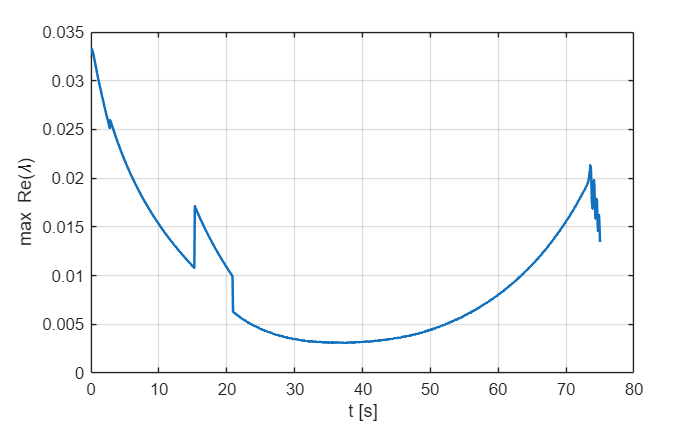

figure;
plot(t_table,max(real_part,[],1), 'LineWidth', 1.5);
xlabel('t [s]'); ylabel('max Re(\lambda)');
grid on;

## **Forward sensitivity ( F(t) )**

A_handle = @(t) A_of_t(t, t_table, A_table);
F0 = eye(n);
F0vec = F0(:);

[tF,Fvec] = ode45(@(t,F) forward_sensitivity(t,F,A_handle,n),tspan,F0vec);

F_t = zeros(n,n,length(tF));

for k = 1:length(tF)
    F_t(:,:,k) = reshape(Fvec(k,:),n,n);
end

Ft_norm = zeros(length(tF),1);

for k=1:length(tF)
    Ft_norm(k) = norm(F_t(:,:,k),2);
end

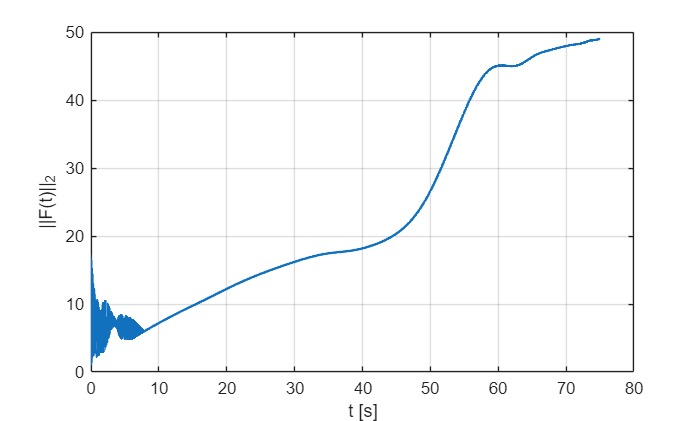

figure;
plot(tF,Ft_norm,'LineWidth', 1.5);
xlabel('t [s]'); ylabel('||F(t)||_2');
grid on;

##  Validation F(t) ( dx_fd (t) )

eps = 1e-6; 
t_common = tF; 

dx_fd = zeros(n,n,length(t_common));
sol_nom = sol;

x_nom_eval = deval(sol_nom, t_common).';

for k = 1:n

    ej = zeros(n,1);
    ej(k) = 1;

    state0_eps = state0 + eps*ej; 

    sol_eps = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), tspan, state0_eps);  

    x_eps_eval = deval(sol_eps, t_common).';

    dx_fd(:,k,:) = ((x_eps_eval - x_nom_eval)/eps).';

end

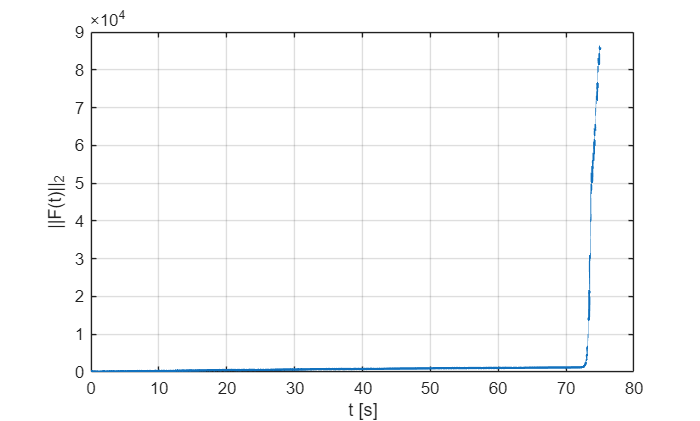

dx_fd_norm = zeros(length(t_common),1);

for k=1:length(t_common)
    dx_fd_norm(k) = norm(dx_fd(:,:,k),2);
end

figure;
plot(t_common,dx_fd_norm,'LineWidth', 1.5);
xlabel('t [s]'); ylabel('||F(t)||_2');
grid on;

## F(t) without interpolation

%% --- F(t)_2 evaluation ---

z0 = [state0;F0vec];

[tz,z] = ode45(@(t,z) augmented_dynamics(t,z,n,f_dyn), tspan, z0);


F_t_2 = zeros(n,n,length(tz));

for k = 1:length(tz)
    F_t_2(:,:,k) = reshape(z(k,n+1:end), n, n);
end

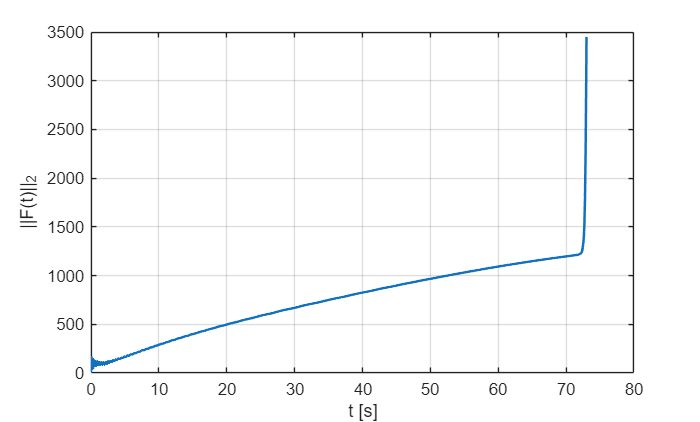

Ft_2_norm = zeros(length(tz),1);

for k=1:length(tz)
    Ft_2_norm(k) = norm(F_t_2(:,:,k),2);
end

idtz = tz <= 73;

figure;
plot(tz(idtz),Ft_2_norm(idtz),'LineWidth', 1.5);
xlabel('t [s]'); ylabel('||F(t)||_2');
grid on;

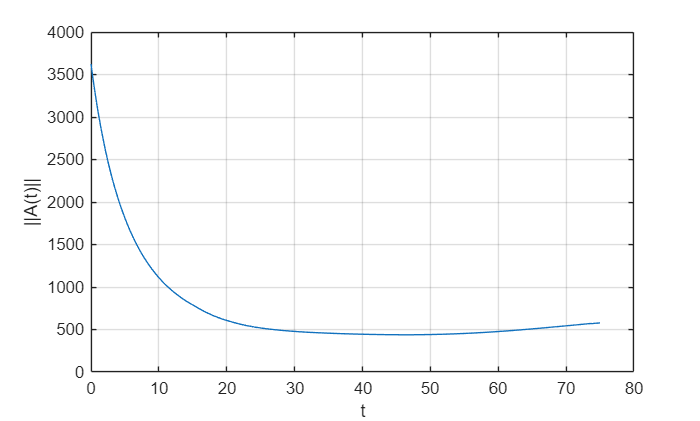

A_norm_2 = zeros(length(tz),1);

for k = 1:length(tz)

    xk = z(k,1:n).';   % estado en ese tiempo
    A  = compute_A_numeric(xk,f_dyn);

    A_norm_2(k) = norm(A);     % o norm(A,'fro')

end

figure;
plot(tz,A_norm_2);
xlabel('t'); ylabel('||A(t)||');
grid on;

## Plots F(t) vs dx_fd(t) vs F_2(t)

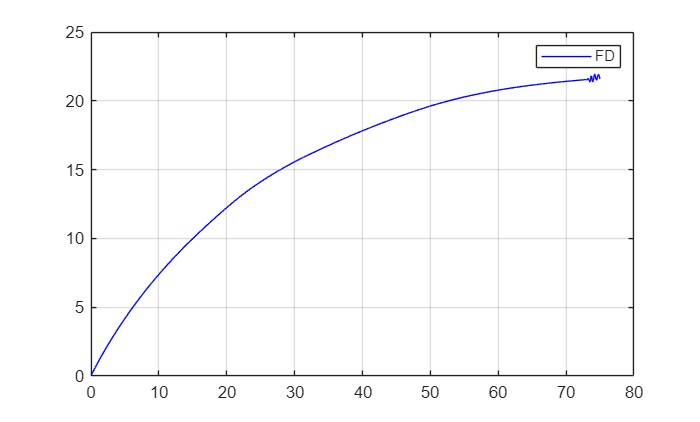

i = 1;   % x position
j = 4;   % vx0
figure;
plot(t_common, squeeze(dx_fd(i,j,:)),'b');
legend('FD');grid on

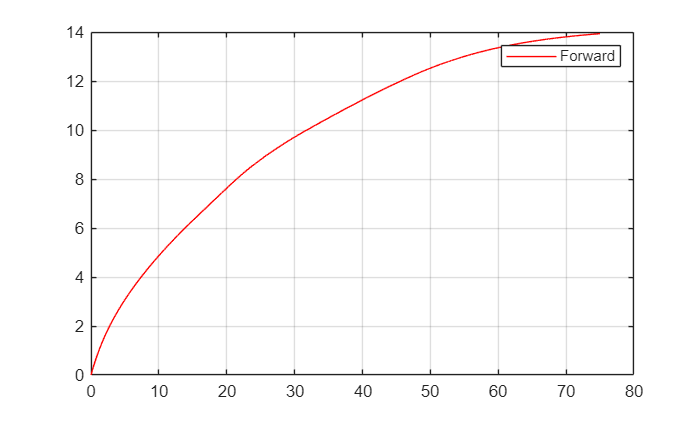

figure;
plot(t_common, squeeze(F_t(i,j,:)), 'r');
legend('Forward');grid on

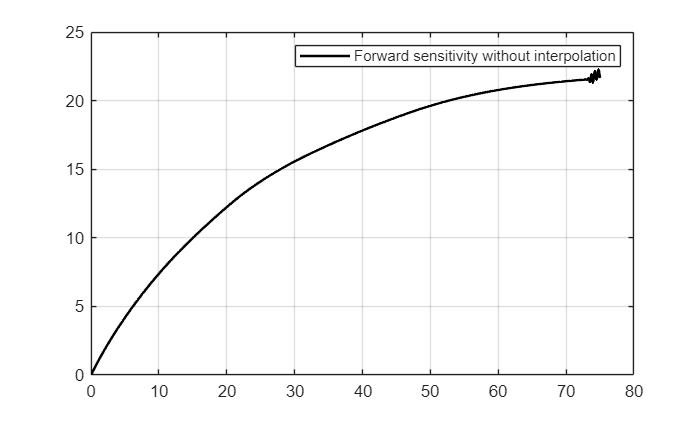

figure;
plot(tz, squeeze(F_t_2(i,j,:)), 'k', 'LineWidth', 1.5);
legend('Forward sensitivity without interpolation');grid on

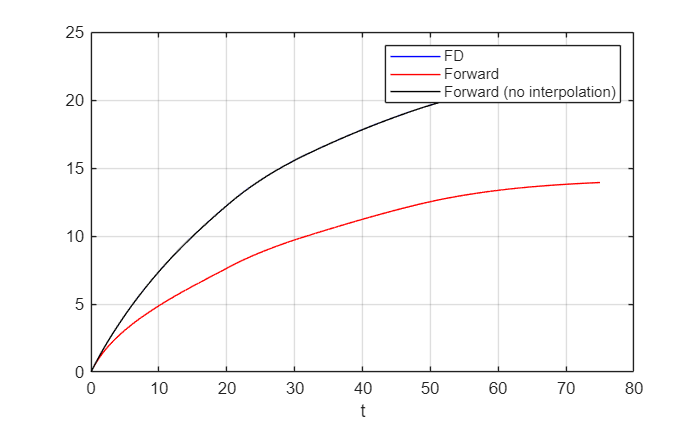

tmax = T;
idx3 = t_common <= tmax;

figure;
plot(t_common(idx3), squeeze(dx_fd(i,j,idx3)), 'b');
hold on
plot(t_common(idx3), squeeze(F_t(i,j,idx3)), 'r');

idx2 = tz <= tmax;

plot(tz(idx2), squeeze(F_t_2(i,j,idx2)), 'k');
legend('FD','Forward','Forward (no interpolation)');
xlabel('t');grid on

## Discrete Impulse Succession (Least Squares)

### Independent Impulse at t = 0 s

delta_cible = zeros(n,1);
delta_cible(1) = 1000;
delta_cible(2) = 2510; % move point of impact in the XY plane

X_cible = Xe' + delta_cible;

F_T = F_t_2(:,:,end); % F(T)

G = F_T(:,4:6); % F(T)*(e4 e5 e6)

c = lsqr(G,delta_cible); % delta_cible = G*c

lsqr converged at iteration 3 to a solution with relative residual 0.42.


delta_x0 = zeros(n,1);
delta_x0(4:6) = c;

state0_pert = state0 + delta_x0;

[t_2, X_2, te_2, Xe_2] = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), [0 200], state0_pert,options);  

error = X_cible - Xe_2'

error =   700.6519
  235.5187
   -0.0000
    0.0546
   -9.2195
    0.3425
   -1.4077
   -0.7211
    0.7897
    0.5822
    7.2009
   -1.9079
  -10.5745


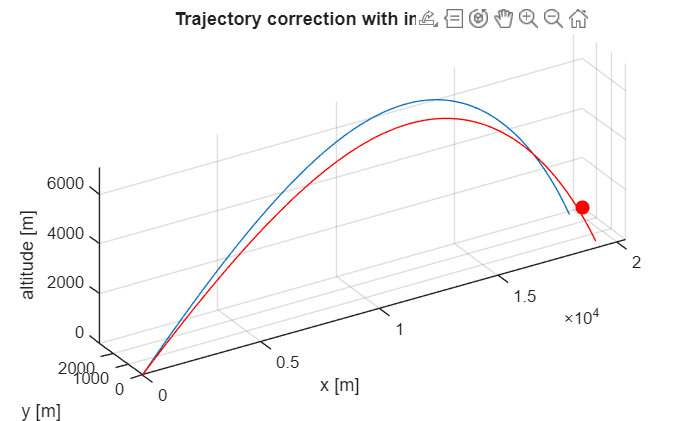

%% --- Perturbed trajectory ---
figure;
plot3(X_2(:,1), X_2(:,2), -X_2(:,3)); grid on; axis equal;
xlabel('x [m]'); ylabel('y [m]'); zlabel('altitude [m]');
title('Trajectory correction with impulse at t = 0 s'); hold on

%% --- Target ---
plot3(X_cible(1),X_cible(2),-X_cible(3),'ro','MarkerSize',8,'MarkerFaceColor','r');

%% --- Nominal trajectory ---
plot3(x, y, altitude,'r');

### Impulsion at t = 10 s

traj_nom = ode45(@(t,z) augmented_dynamics(t,z,n,f_dyn), tspan, z0); % do not touch

z_10 = deval(traj_nom,10);

x_10 = z_10(1:n);

F_10 = reshape(z_10(n+1:end),n,n);

F_T10 = F_T/F_10;

idx = 1:2; % XY grid

G_10 = F_T10(:,4:6); % F(T)*(e4 e5 e6)

c_10 = lsqr(G_10(idx,:),delta_cible(idx)) % delta_cible = G*c

lsqr converged at iteration 2 to a solution with relative residual 1.5e-16.


c_10 =    45.8055
   60.4130
   -7.5851


delta_x10 = zeros(n,1);
delta_x10(4:6) = c_10;

state0_10 = x_10 + delta_x10;

z10_new = [state0_10;F0vec];

traj_10 = ode45(@(t,z) augmented_dynamics(t,z,n,f_dyn), [10 200], z10_new, options); 

Xe_10 = traj_10.ye(1:n,end);

error_10 = X_cible-Xe_10

error_10 =  -148.8145
  222.3921
    0.0000
   -0.5692
  -18.6760
    1.0088
   -0.4017
   -0.7133
    1.4745
   -0.2472
   22.8736
   15.3266
   -5.4000


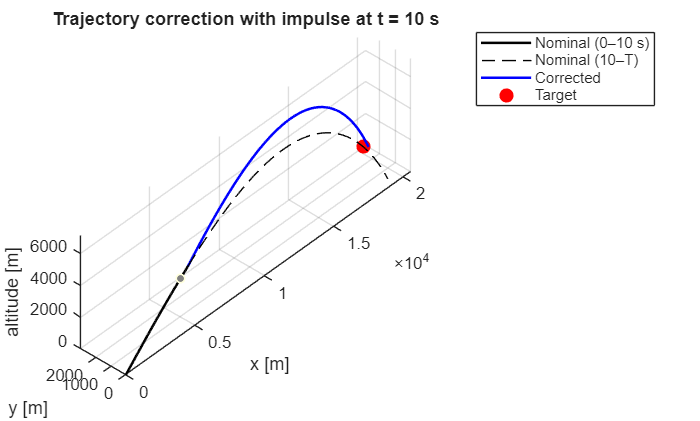

%% --- Nominal trajectory ---

figure; 
idx10 = traj_nom.x <= 10;
X_nom_plot = deval(traj_nom, traj_nom.x(idx10)).';

plot3(X_nom_plot(:,1), ...
      X_nom_plot(:,2), ...
     -X_nom_plot(:,3), 'k', 'LineWidth',1.5); 
hold on

idx10p = traj_nom.x >= 10;
X_nom_post = deval(traj_nom, traj_nom.x(idx10p)).';

plot3(X_nom_post(:,1), ...
      X_nom_post(:,2), ...
     -X_nom_post(:,3), 'k--');

%% --- Perturbed trajectory ---

X_10 = traj_10.y(1:n,:).';

plot3(X_10(:,1), X_10(:,2), -X_10(:,3),'b', 'LineWidth',1.5);

% --- Target ---

plot3(X_cible(1),X_cible(2),-X_cible(3),'ro','MarkerSize',8,'MarkerFaceColor','r');

grid on; axis equal
xlabel('x [m]'); ylabel('y [m]'); zlabel('altitude [m]');
legend('Nominal (0–10 s)', 'Nominal (10–T)', ...
       'Corrected', 'Target');
title('Trajectory correction with impulse at t = 10 s');

### Impulsion at t = 20 s

z_20 = deval(traj_10,20);

x_20 = z_20(1:n);

F_20 = reshape(z_20(n+1:end),n,n);

F_T_traj10 = reshape(traj_10.ye(n+1:end,end),n,n);

F_T20 = F_T_traj10/F_20;
G_20 = F_T20(:,4:6); % F(T)*(e4 e5 e6)

delta_cible_traj10 = error_10;

c_20 = lsqr(G_20(idx,:),delta_cible_traj10(idx)) % delta_cible = G*c
delta_x20 = zeros(n,1);
delta_x20(4:6) = c_20;

state0_20 = x_20 + delta_x20;

z20_new = [state0_20;F0vec];



traj_20 = ode45(@(t,z) augmented_dynamics(t,z,n,f_dyn), [20 200], z20_new, options); 

Xe_20 = traj_20.ye(1:n,end);

error_20 = X_cible-Xe_20

error_20 =    25.5310
    4.0623
   -0.0000
   -3.4745
  -13.6566
    1.9173
   -1.5112
   -0.2938
    0.4460
    0.2225
   20.6943
    6.2471
  -15.8062


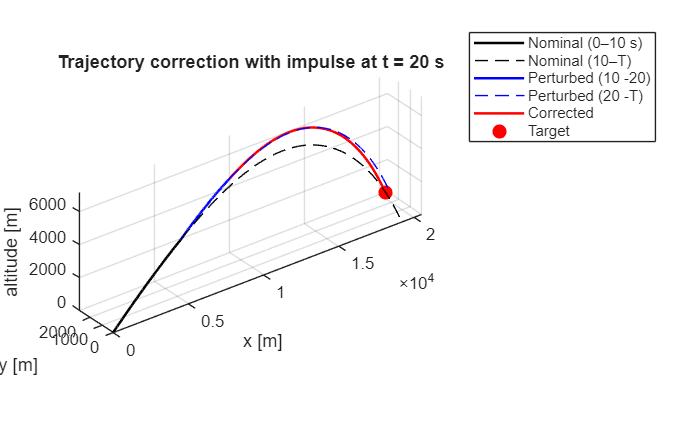

%% --- Nominal trajectory ---
figure; 
idx10 = traj_nom.x <= 10;
X_nom_plot = deval(traj_nom, traj_nom.x(idx10)).';

plot3(X_nom_plot(:,1), ...
      X_nom_plot(:,2), ...
     -X_nom_plot(:,3), 'k', 'LineWidth',1.5); 
hold on

idx10p = traj_nom.x >= 10;
X_nom_post = deval(traj_nom, traj_nom.x(idx10p)).';

plot3(X_nom_post(:,1), ...
      X_nom_post(:,2), ...
     -X_nom_post(:,3), 'k--');

%% --- Perturbed trajectory at 10 s ---

idx20 = traj_10.x <= 20;

X_10_plot = deval(traj_10, traj_10.x(idx20)).';

plot3(X_10_plot(:,1), X_10_plot(:,2), -X_10_plot(:,3),'b', 'LineWidth',1.5);

idx20p = traj_10.x >= 20;

X_10_post = deval(traj_10, traj_10.x(idx20p)).';

plot3(X_10_post(:,1), ...
      X_10_post(:,2), ...
     -X_10_post(:,3), 'b--');

%% --- Perturbed trajectory at 20 s---

X_20 = traj_20.y(1:n,:).';

plot3(X_20(:,1), X_20(:,2), -X_20(:,3),'r', 'LineWidth',1.5);

% --- Target ---

plot3(X_cible(1),X_cible(2),-X_cible(3),'ro','MarkerSize',8,'MarkerFaceColor','r');

grid on; axis equal
xlabel('x [m]'); ylabel('y [m]'); zlabel('altitude [m]');
legend('Nominal (0–10 s)', 'Nominal (10–T)', 'Perturbed (10 -20)','Perturbed (20 -T)','Corrected', 'Target');
title('Trajectory correction with impulse at t = 20 s');

### Impulsion at t = 30 s

z_30 = deval(traj_20,30);

x_30 = z_30(1:n);

F_30 = reshape(z_30(n+1:end),n,n);

F_T_traj20 = reshape(traj_20.ye(n+1:end,end),n,n);

F_T30 = F_T_traj20/F_30;
G_30 = F_T30(:,4:6); % F(T)*(e4 e5 e6)

delta_cible_traj20 = error_20;

c_30 = lsqr(G_30(idx,:),delta_cible_traj20(idx)) % delta_cible = G*c
delta_x30 = zeros(n,1);
delta_x30(4:6) = c_30;

state0_30 = x_30 + delta_x30;

z30_new = [state0_30;F0vec];


traj_30 = ode45(@(t,z) augmented_dynamics(t,z,n,f_dyn), [30 200], z30_new, options); 

Xe_30 = traj_30.ye(1:n,end);

error_30 = X_cible-Xe_30

error_30 =    -7.2842
   -1.3680
   -0.0000
   -6.5419
  -15.5034
    3.5062
    0.2110
   -0.6955
    0.7512
    0.7878
   21.1326
   13.9161
  -12.0302


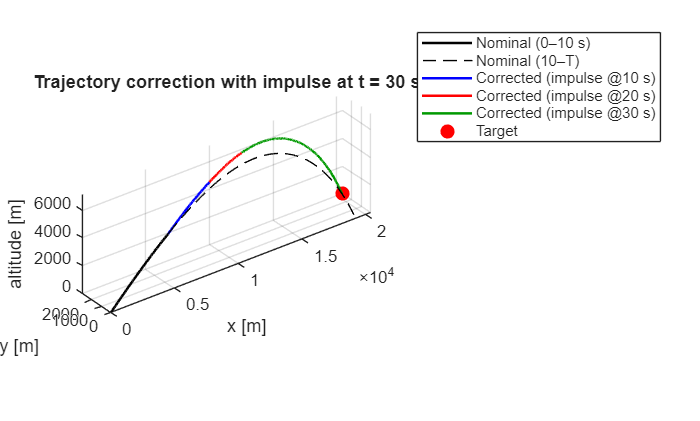

%% --- Nominal trajectory ---
figure; 
idx10 = traj_nom.x <= 10;
X_nom_plot = deval(traj_nom, traj_nom.x(idx10)).';

plot3(X_nom_plot(:,1), ...
      X_nom_plot(:,2), ...
     -X_nom_plot(:,3), 'k', 'LineWidth',1.5); 
hold on

idx10p = traj_nom.x >= 10;
X_nom_post = deval(traj_nom, traj_nom.x(idx10p)).';

plot3(X_nom_post(:,1), ...
      X_nom_post(:,2), ...
     -X_nom_post(:,3), 'k--');

%% --- Perturbed trajectory at 10 s ---

idx20 = traj_10.x <= 20;

X_10_plot = deval(traj_10, traj_10.x(idx20)).';

plot3(X_10_plot(:,1), X_10_plot(:,2), -X_10_plot(:,3),'b', 'LineWidth',1.5);

%% --- Perturbed trajectory at 20 s---

idx30 = traj_20.x <= 30;

X_20_plot = deval(traj_20, traj_20.x(idx30)).';

plot3(X_20_plot(:,1), X_20_plot(:,2), -X_20_plot(:,3),'r', 'LineWidth',1.5);

%% --- Perturbed trajectory at 30 s---

X_30 = traj_30.y(1:n,:).';

plot3(X_30(:,1), X_30(:,2), -X_30(:,3),'Color',[0 0.6 0], 'LineWidth',1.5);

% --- Target ---

plot3(X_cible(1),X_cible(2),-X_cible(3),'ro','MarkerSize',8,'MarkerFaceColor','r');

grid on; axis equal
xlabel('x [m]'); ylabel('y [m]'); zlabel('altitude [m]');
legend('Nominal (0–10 s)', 'Nominal (10–T)','Corrected (impulse @10 s)','Corrected (impulse @20 s)', ...
    'Corrected (impulse @30 s)','Target');
title('Trajectory correction with impulse at t = 30 s');

### Impulsion at t = 40 s

z_40 = deval(traj_30,40);

x_40 = z_40(1:n);

F_40 = reshape(z_40(n+1:end),n,n);

F_T_traj30 = reshape(traj_30.ye(n+1:end,end),n,n);

F_T40 = F_T_traj30/F_40;
G_40 = F_T40(:,4:6); % F(T)*(e4 e5 e6)

delta_cible_traj30 = error_30;

c_40 = lsqr(G_40(idx,:),delta_cible_traj30(idx)); % delta_cible = G*c
delta_x40 = zeros(n,1);
delta_x40(4:6) = c_40;

state0_40 = x_40 + delta_x40;

z40_new = [state0_40;F0vec];

traj_40 = ode45(@(t,z) augmented_dynamics(t,z,n,f_dyn), [40 200], z40_new, options); 

Xe_40 = traj_40.ye(1:n,end);

error_40 = X_cible-Xe_40

error_40 =     1.9339
    0.3714
    0.0000
   -6.1897
  -15.1074
    3.2998
   -0.7336
   -1.1745
    0.2698
    0.4364
   21.0215
    2.8486
    1.1300


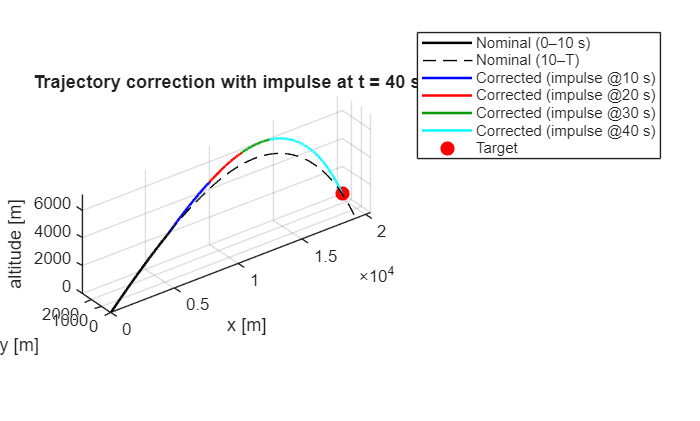

%% --- Nominal trajectory ---
figure; 
idx10 = traj_nom.x <= 10;
X_nom_plot = deval(traj_nom, traj_nom.x(idx10)).';

plot3(X_nom_plot(:,1), ...
      X_nom_plot(:,2), ...
     -X_nom_plot(:,3), 'k', 'LineWidth',1.5); 
hold on

idx10p = traj_nom.x >= 10;
X_nom_post = deval(traj_nom, traj_nom.x(idx10p)).';

plot3(X_nom_post(:,1), ...
      X_nom_post(:,2), ...
     -X_nom_post(:,3), 'k--');

%% --- Perturbed trajectory at 10 s ---

idx20 = traj_10.x <= 20;

X_10_plot = deval(traj_10, traj_10.x(idx20)).';

plot3(X_10_plot(:,1), X_10_plot(:,2), -X_10_plot(:,3),'b', 'LineWidth',1.5);

%% --- Perturbed trajectory at 20 s---

idx30 = traj_20.x <= 30;

X_20_plot = deval(traj_20, traj_20.x(idx30)).';

plot3(X_20_plot(:,1), X_20_plot(:,2), -X_20_plot(:,3),'r', 'LineWidth',1.5);

%% --- Perturbed trajectory at 30 s---

idx40 = traj_30.x <= 40;

X_30_plot = deval(traj_30, traj_30.x(idx40)).';

plot3(X_30_plot(:,1), X_30_plot(:,2), -X_30_plot(:,3),'Color',[0 0.6 0], 'LineWidth',1.5);

%% --- Perturbed trajectory at 40 s---

X_40 = traj_40.y(1:n,:).';

plot3(X_40(:,1), X_40(:,2), -X_40(:,3),'c', 'LineWidth',1.5);

% --- Target ---

plot3(X_cible(1),X_cible(2),-X_cible(3),'ro','MarkerSize',8,'MarkerFaceColor','r');

grid on; axis equal
xlabel('x [m]'); ylabel('y [m]'); zlabel('altitude [m]');
legend('Nominal (0–10 s)', 'Nominal (10–T)','Corrected (impulse @10 s)','Corrected (impulse @20 s)', ...
    'Corrected (impulse @30 s)','Corrected (impulse @40 s)','Target');
title('Trajectory correction with impulse at t = 40 s');

### Impulsion at t = 50 s

z_50 = deval(traj_40,50);

x_50 = z_50(1:n);

F_50 = reshape(z_50(n+1:end),n,n);

F_T_traj40 = reshape(traj_40.ye(n+1:end,end),n,n);

F_T50 = F_T_traj40/F_50;
G_50 = F_T50(:,4:6); % F(T)*(e4 e5 e6)

delta_cible_traj40 = error_40;

c_50 = lsqr(G_50(idx,:),delta_cible_traj40(idx)); % delta_cible = G*c
delta_x50 = zeros(n,1);
delta_x50(4:6) = c_50;

state0_50 = x_50 + delta_x50;

z50_new = [state0_50;F0vec];

traj_50 = ode45(@(t,z) augmented_dynamics(t,z,n,f_dyn), [50 200], z50_new, options); 

Xe_50 = traj_50.ye(1:n,end);

error_50 = X_cible-Xe_50

error_50 =    -0.4296
   -0.0853
    0.0000
   -6.3743
  -15.3085
    3.4069
   -0.4343
   -1.1739
    0.3289
    0.5796
   21.0487
    8.7732
    1.7255


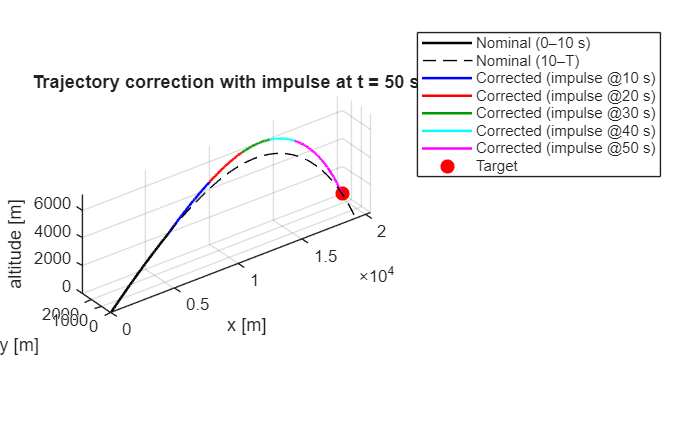

%% --- Nominal trajectory ---
figure; 
idx10 = traj_nom.x <= 10;
X_nom_plot = deval(traj_nom, traj_nom.x(idx10)).';

plot3(X_nom_plot(:,1), ...
      X_nom_plot(:,2), ...
     -X_nom_plot(:,3), 'k', 'LineWidth',1.5); 
hold on

idx10p = traj_nom.x >= 10;
X_nom_post = deval(traj_nom, traj_nom.x(idx10p)).';

plot3(X_nom_post(:,1), ...
      X_nom_post(:,2), ...
     -X_nom_post(:,3), 'k--');

%% --- Perturbed trajectory at 10 s ---

idx20 = traj_10.x <= 20;

X_10_plot = deval(traj_10, traj_10.x(idx20)).';

plot3(X_10_plot(:,1), X_10_plot(:,2), -X_10_plot(:,3),'b', 'LineWidth',1.5);

%% --- Perturbed trajectory at 20 s---

idx30 = traj_20.x <= 30;

X_20_plot = deval(traj_20, traj_20.x(idx30)).';

plot3(X_20_plot(:,1), X_20_plot(:,2), -X_20_plot(:,3),'r', 'LineWidth',1.5);

%% --- Perturbed trajectory at 30 s---

idx40 = traj_30.x <= 40;

X_30_plot = deval(traj_30, traj_30.x(idx40)).';

plot3(X_30_plot(:,1), X_30_plot(:,2), -X_30_plot(:,3),'Color',[0 0.6 0], 'LineWidth',1.5);

%% --- Perturbed trajectory at 40 s---

idx50 = traj_40.x <= 50;

X_40_plot = deval(traj_40, traj_40.x(idx50)).';

plot3(X_40_plot(:,1), X_40_plot(:,2), -X_40_plot(:,3),'c', 'LineWidth',1.5);

%% --- Perturbed trajectory at 50 s---

X_50 = traj_50.y(1:n,:).';

plot3(X_50(:,1), X_50(:,2), -X_50(:,3),'m', 'LineWidth',1.5);

% --- Target ---

plot3(X_cible(1),X_cible(2),-X_cible(3),'ro','MarkerSize',8,'MarkerFaceColor','r');

grid on; axis equal
xlabel('x [m]'); ylabel('y [m]'); zlabel('altitude [m]');
legend('Nominal (0–10 s)', 'Nominal (10–T)','Corrected (impulse @10 s)','Corrected (impulse @20 s)', ...
    'Corrected (impulse @30 s)','Corrected (impulse @40 s)','Corrected (impulse @50 s)','Target');
title('Trajectory correction with impulse at t = 50 s');

### Impulsion at t = 60 s

z_60 = deval(traj_50,60);

x_60 = z_60(1:n);

F_60 = reshape(z_60(n+1:end),n,n);

F_T_traj50 = reshape(traj_50.ye(n+1:end,end),n,n);

F_T60 = F_T_traj50/F_60;
G_60 = F_T60(:,4:6); % F(T)*(e4 e5 e6)

delta_cible_traj50 = error_50;

c_60 = lsqr(G_60(idx,:),delta_cible_traj50(idx)) % delta_cible = G*c
delta_x60 = zeros(n,1);
delta_x60(4:6) = c_60;

state0_60 = x_60 + delta_x60;

z60_new = [state0_60;F0vec];

traj_60 = ode45(@(t,z) augmented_dynamics(t,z,n,f_dyn), [60 200], z60_new, options); 

Xe_60 = traj_60.ye(1:n,end);

error_60 = X_cible-Xe_60

error_60 =     0.0661
    0.0145
    0.0000
   -6.4166
  -15.3968
    3.4359
   -0.5140
   -1.1758
    0.2890
    0.5393
   21.0426
    7.1000
    1.9723


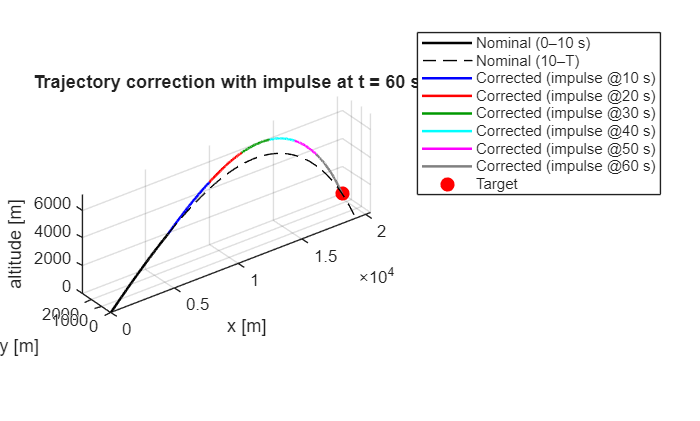

%% --- Nominal trajectory ---
figure; 
idx10 = traj_nom.x <= 10;
X_nom_plot = deval(traj_nom, traj_nom.x(idx10)).';

plot3(X_nom_plot(:,1), ...
      X_nom_plot(:,2), ...
     -X_nom_plot(:,3), 'k', 'LineWidth',1.5); 
hold on

idx10p = traj_nom.x >= 10;
X_nom_post = deval(traj_nom, traj_nom.x(idx10p)).';

plot3(X_nom_post(:,1), ...
      X_nom_post(:,2), ...
     -X_nom_post(:,3), 'k--');

%% --- Perturbed trajectory at 10 s ---

idx20 = traj_10.x <= 20;

X_10_plot = deval(traj_10, traj_10.x(idx20)).';

plot3(X_10_plot(:,1), X_10_plot(:,2), -X_10_plot(:,3),'b', 'LineWidth',1.5);

%% --- Perturbed trajectory at 20 s---

idx30 = traj_20.x <= 30;

X_20_plot = deval(traj_20, traj_20.x(idx30)).';

plot3(X_20_plot(:,1), X_20_plot(:,2), -X_20_plot(:,3),'r', 'LineWidth',1.5);

%% --- Perturbed trajectory at 30 s---

idx40 = traj_30.x <= 40;

X_30_plot = deval(traj_30, traj_30.x(idx40)).';

plot3(X_30_plot(:,1), X_30_plot(:,2), -X_30_plot(:,3),'Color',[0 0.6 0], 'LineWidth',1.5);

%% --- Perturbed trajectory at 40 s---

idx50 = traj_40.x <= 50;

X_40_plot = deval(traj_40, traj_40.x(idx50)).';

plot3(X_40_plot(:,1), X_40_plot(:,2), -X_40_plot(:,3),'c', 'LineWidth',1.5);

%% --- Perturbed trajectory at 50 s---

idx60 = traj_50.x <= 60;

X_50_plot = deval(traj_50, traj_50.x(idx60)).';

plot3(X_50_plot(:,1), X_50_plot(:,2), -X_50_plot(:,3),'m', 'LineWidth',1.5);

%% --- Perturbed trajectory at 60 s---

X_60 = traj_60.y(1:n,:).';

plot3(X_60(:,1), X_60(:,2), -X_60(:,3),'Color',[0.5 0.5 0.5], 'LineWidth',1.5);

% --- Target ---

plot3(X_cible(1),X_cible(2),-X_cible(3),'ro','MarkerSize',8,'MarkerFaceColor','r');

grid on; axis equal
xlabel('x [m]'); ylabel('y [m]'); zlabel('altitude [m]');
legend('Nominal (0–10 s)', 'Nominal (10–T)','Corrected (impulse @10 s)','Corrected (impulse @20 s)', ...
    'Corrected (impulse @30 s)','Corrected (impulse @40 s)','Corrected (impulse @50 s)',...
    'Corrected (impulse @60 s)','Target');
title('Trajectory correction with impulse at t = 60 s');

## Error vs Impulse

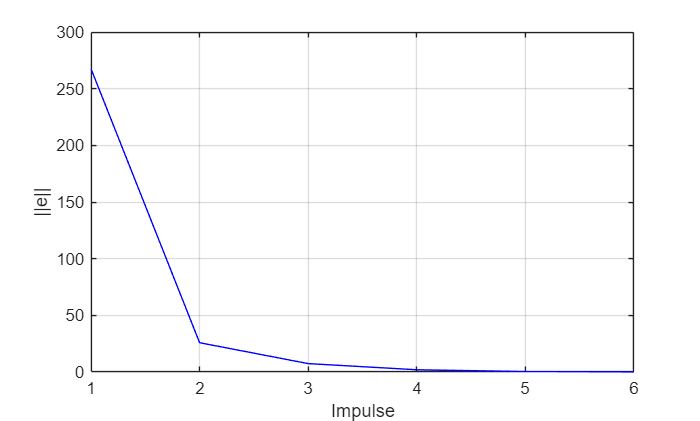

err_total = [error_10 error_20 error_30 error_40 error_50 error_60];
norm_err = zeros(6,1);

for k = 1:6
    norm_err(k) = norm(err_total(idx,k));
end

figure;
plot(norm_err,'b'); grid on;
xlabel('Impulse'); ylabel('||e||');

## Norm c vs Impulse

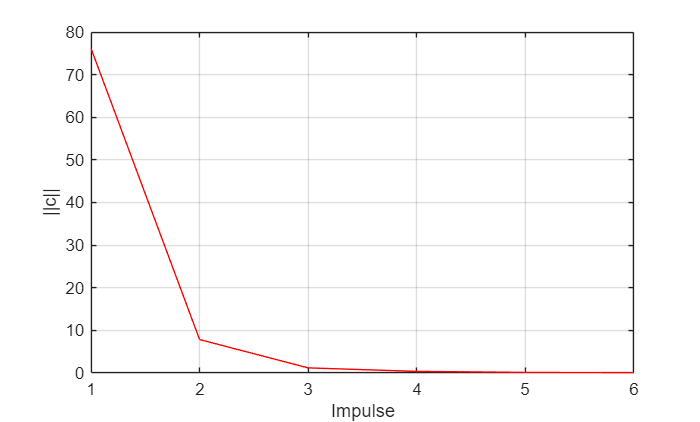

c_tot =[c_10 c_20 c_30 c_40 c_50 c_60];
norm_c = zeros(6,1);

for k = 1:6
    norm_c(k) = norm(c_tot(:,k));
end

figure;
plot(norm_c,'r');grid on;
xlabel('Impulse'); ylabel('||c||');

## Realistic constraints

### Constants

traj_nom = ode45(@(t,z) augmented_dynamics(t,z,n,f_dyn), tspan, z0); % do not touch

retard = 0.5;
W = diag([1,1,100]);
idx = 1:2; % XY grid
r_max_exag = 30000;
theta_vec = linspace(0, 2*pi, 60); % résolution angulaire
X_nom = Xe';

### Independent Impulsion at t = 10 s

z_10_0 = deval(traj_nom,10);

x_10_0 = z_10_0(1:n);

v_10_0 = x_10_0(4:6);

v_10_0_nom = norm(v_10_0);

z_10_ret = deval(traj_nom, 10 + retard);

x_10_ret = z_10_ret(1:n);

F_10_0 = reshape(z_10_0(n+1:end),n,n);

F_T_10 = F_T/F_10_0;


G_T_10 = F_T_10(:,4:6); % F(T)*(e4 e5 e6)

c_T_10 = inv(G_T_10(idx,:)'*G_T_10(idx,:)+W)*G_T_10(idx,:)'*delta_cible(idx) % delta_cible = G*c

c_T_10 =    46.5722
   60.6791
   -0.0768


cmax10 = 0.3*v_10_0_nom

cmax10 = 141.3114

if norm(c_T_10) > cmax10
    c_T_10 = cmax10 * c_T_10/norm(c_T_10);
end 

delta_x_T_10 = zeros(n,1);

delta_x_T_10(4:6) = c_T_10;

state0_T_10 = x_10_ret + delta_x_T_10;

[t_T_10, X_T_10, te_T_10, Xe_T_10] = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), [10 200], state0_T_10,options);  

error_T_10 = X_cible - Xe_T_10'

error_T_10 =     7.2879
  241.9968
    0.0000
   -8.8187
  -18.3465
    5.4302
   -0.4868
    0.1694
    1.5854
    0.3821
   21.1082
    1.1028
   -0.0286


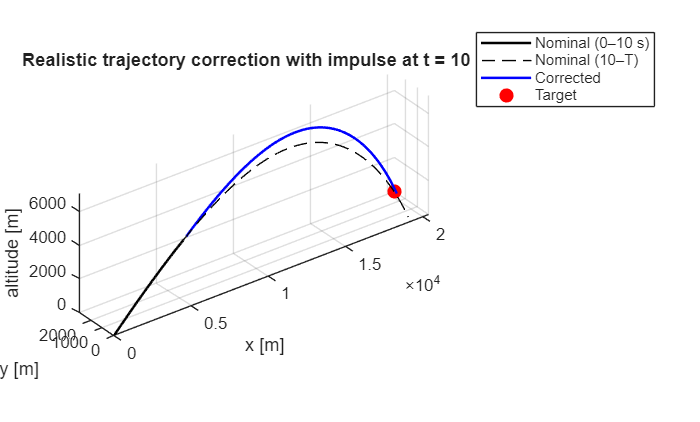

%% --- Nominal trajectory ---

figure; 
idx10 = traj_nom.x <= 10;
X_nom_plot = deval(traj_nom, traj_nom.x(idx10)).';

plot3(X_nom_plot(:,1), ...
      X_nom_plot(:,2), ...
     -X_nom_plot(:,3), 'k', 'LineWidth',1.5); 
hold on

idx10p = traj_nom.x >= 10;
X_nom_post = deval(traj_nom, traj_nom.x(idx10p)).';

plot3(X_nom_post(:,1), ...
      X_nom_post(:,2), ...
     -X_nom_post(:,3), 'k--');

%% --- Perturbed trajectory ---

plot3(X_T_10(:,1), X_T_10(:,2), -X_T_10(:,3),'b','LineWidth',1.5);

% --- Target ---

plot3(X_cible(1),X_cible(2),-X_cible(3),'ro','MarkerSize',8,'MarkerFaceColor','r');

grid on; axis equal
xlabel('x [m]'); ylabel('y [m]'); zlabel('altitude [m]');
legend('Nominal (0–10 s)', 'Nominal (10–T)', ...
       'Corrected', 'Target');
title('Realistic trajectory correction with impulse at t = 10 s');

### Admissible frontiere at max energy

X_front_T_10 = zeros(2, length(theta_vec));

for k = 1:length(theta_vec)

    theta = theta_vec(k);
    u = [cos(theta);sin(theta)];

    c_T_10 = inv(G_T_10(idx,:)'*G_T_10(idx,:)+W)*G_T_10(idx,:)'*r_max_exag*u; % delta_cible = G*c 
    
    if norm(c_T_10) > cmax10
        c_T_10 = cmax10 * c_T_10/norm(c_T_10);
        disp(['Iteración k = ', num2str(k)]);
    end 
    
    delta_x_T_10 = zeros(n,1);
    
    delta_x_T_10(4:6) = c_T_10;
    
    state0_T_10 = x_10_ret + delta_x_T_10;

    [t_T_10, X_T_10, te_T_10, Xe_T_10] = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), [10 200], state0_T_10,options); 
    
    X_front_T_10(:,k) = Xe_T_10(:,idx)';
end

Iteración k = 1
Iteración k = 2
Iteración k = 3
Iteración k = 4
Iteración k = 5
Iteración k = 6
Iteración k = 7
Iteración k = 8
Iteración k = 9
Iteración k = 10
Iteración k = 11
Iteración k = 12
Iteración k = 13
Iteración k = 14
Iteración k = 15
Iteración k = 16
Iteración k = 17
Iteración k = 18
Iteración k = 19
Iteración k = 20
Iteración k = 21
Iteración k = 22
Iteración k = 23
Iteración k = 24
Iteración k = 25
Iteración k = 26
Iteración k = 27
Iteración k = 28
Iteración k = 29
Iteración k = 30
Iteración k = 31
Iteración k = 32
Iteración k = 33
Iteración k = 34
Iteración k = 35
Iteración k = 36
Iteración k = 37
Iteración k = 38
Iteración k = 39
Iteración k = 40
Iteración k = 41
Iteración k = 42
Iteración k = 43
Iteración k = 44
Iteración k = 45
Iteración k = 46
Iteración k = 47
Iteración k = 48
Iteración k = 49
Iteración k = 50
Iteración k = 51
Iteración k = 52
Iteración k = 53
Iteración k = 54
Iteración k = 55
Iteración k = 56
Iteración k = 57
Iteración k = 58
Iteración k = 59
Iterac

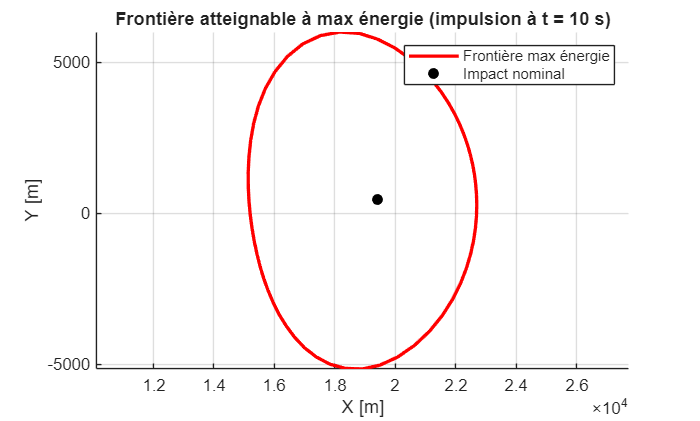

figure; hold on; grid on; axis equal
plot(X_front_T_10(1,:), X_front_T_10(2,:), 'r', 'LineWidth', 2)
plot(X_nom(1), X_nom(2), 'ko', 'MarkerFaceColor','k')

xlabel('X [m]')
ylabel('Y [m]')
title("Frontière atteignable à max énergie (impulsion à t = 10 s)")
legend('Frontière max énergie', 'Impact nominal')

### Independent Impulsion at t = 20 s

z_20_0 = deval(traj_nom,20);

x_20_0 = z_20_0(1:n);

v_20_0 = x_20_0(4:6);

v_20_0_nom = norm(v_20_0);

z_20_ret = deval(traj_nom, 20 + retard);

x_20_ret = z_20_ret(1:n);

F_20_0 = reshape(z_20_0(n+1:end),n,n);

F_T_20 = F_T/F_20_0;


G_T_20 = F_T_20(:,4:6); % F(T)*(e4 e5 e6)

c_T_20 = inv(G_T_20(idx,:)'*G_T_20(idx,:)+W)*G_T_20(idx,:)'*delta_cible(idx) % delta_cible = G*c

c_T_20 =    66.2787
   54.7807
   -0.0219



cmax20 = 0.3*v_20_0_nom

cmax20 = 97.4270


if norm(c_T_20) > cmax20
    c_T_20 = cmax20 * c_T_20/norm(c_T_20);
end 

delta_x_T_20 = zeros(n,1);

delta_x_T_20(4:6) = c_T_20;

state0_T_20 = x_20_ret + delta_x_T_20;

[t_T_20, X_T_20, te_T_20, Xe_T_20] = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), [20 200], state0_T_20,options);  

error_T_20 = X_cible - Xe_T_20'

error_T_20 =  -378.4087
  609.7957
   -0.0000
   -4.1315
  -17.2353
    3.0110
   -0.5049
    0.3200
   -0.0231
    0.0888
   28.9455
    7.7436
    1.3695


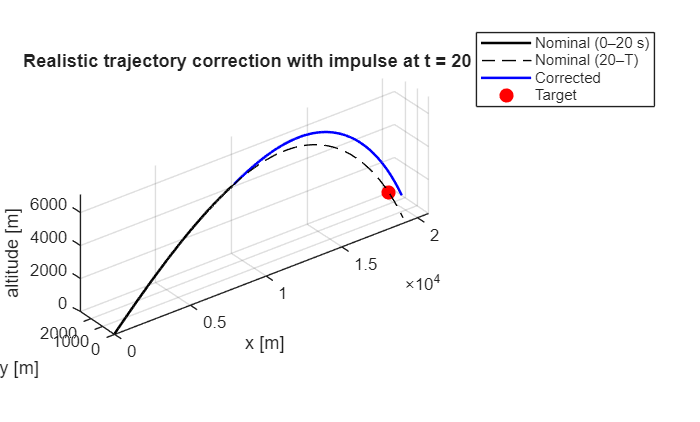

%% --- Nominal trajectory ---

figure; 
idx20 = traj_nom.x <= 20;
X_nom_plot = deval(traj_nom, traj_nom.x(idx20)).';

plot3(X_nom_plot(:,1), ...
      X_nom_plot(:,2), ...
     -X_nom_plot(:,3), 'k', 'LineWidth',1.5); 
hold on

idx20p = traj_nom.x >= 20;
X_nom_post = deval(traj_nom, traj_nom.x(idx20p)).';

plot3(X_nom_post(:,1), ...
      X_nom_post(:,2), ...
     -X_nom_post(:,3), 'k--');

%% --- Perturbed trajectory ---

plot3(X_T_20(:,1), X_T_20(:,2), -X_T_20(:,3),'b','LineWidth',1.5);

% --- Target ---

plot3(X_cible(1),X_cible(2),-X_cible(3),'ro','MarkerSize',8,'MarkerFaceColor','r');

grid on; axis equal
xlabel('x [m]'); ylabel('y [m]'); zlabel('altitude [m]');
legend('Nominal (0–20 s)', 'Nominal (20–T)', ...
       'Corrected', 'Target');
title('Realistic trajectory correction with impulse at t = 20 s');

### Admissible frontiere at max energy

X_front_T_20 = zeros(2, length(theta_vec));

for k = 1:length(theta_vec)

    theta = theta_vec(k);
    u = [cos(theta);sin(theta)];

    c_T_20 = inv(G_T_20(idx,:)'*G_T_20(idx,:)+W)*G_T_20(idx,:)'*r_max_exag*u; % delta_cible = G*c 
    
    if norm(c_T_20) > cmax20
        c_T_20 = cmax20 * c_T_20/norm(c_T_20);
        disp(['Iteración k = ', num2str(k)]);
    end 
    
    delta_x_T_20 = zeros(n,1);
    
    delta_x_T_20(4:6) = c_T_20;
    
    state0_T_20 = x_20_ret + delta_x_T_20;

    [t_T_20, X_T_20, te_T_20, Xe_T_20] = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), [20 200], state0_T_20,options); 
    
    X_front_T_20(:,k) = Xe_T_20(:,idx)';
end

Iteración k = 1
Iteración k = 2
Iteración k = 3
Iteración k = 4
Iteración k = 5
Iteración k = 6
Iteración k = 7
Iteración k = 8
Iteración k = 9
Iteración k = 10
Iteración k = 11
Iteración k = 12
Iteración k = 13
Iteración k = 14
Iteración k = 15
Iteración k = 16
Iteración k = 17
Iteración k = 18
Iteración k = 19
Iteración k = 20
Iteración k = 21
Iteración k = 22
Iteración k = 23
Iteración k = 24
Iteración k = 25
Iteración k = 26
Iteración k = 27
Iteración k = 28
Iteración k = 29
Iteración k = 30
Iteración k = 31
Iteración k = 32
Iteración k = 33
Iteración k = 34
Iteración k = 35
Iteración k = 36
Iteración k = 37
Iteración k = 38
Iteración k = 39
Iteración k = 40
Iteración k = 41
Iteración k = 42
Iteración k = 43
Iteración k = 44
Iteración k = 45
Iteración k = 46
Iteración k = 47
Iteración k = 48
Iteración k = 49
Iteración k = 50
Iteración k = 51
Iteración k = 52
Iteración k = 53
Iteración k = 54
Iteración k = 55
Iteración k = 56
Iteración k = 57
Iteración k = 58
Iteración k = 59
Iterac

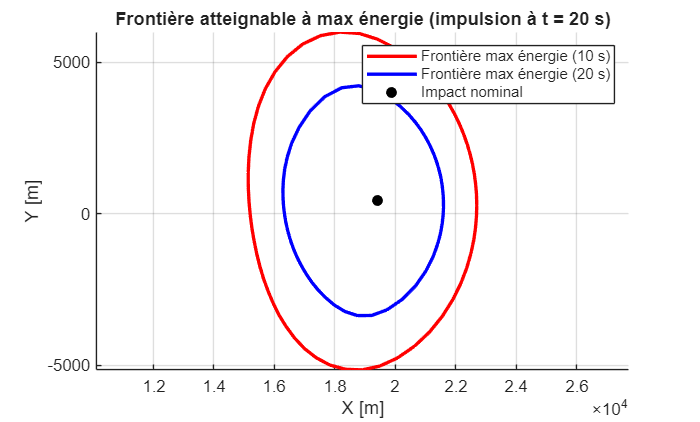

figure; hold on; grid on; axis equal
plot(X_front_T_10(1,:), X_front_T_10(2,:), 'r', 'LineWidth', 2)
plot(X_front_T_20(1,:), X_front_T_20(2,:), 'b', 'LineWidth', 2)
plot(X_nom(1), X_nom(2), 'ko', 'MarkerFaceColor','k')

xlabel('X [m]')
ylabel('Y [m]')
title("Frontière atteignable à max énergie (impulsion à t = 20 s)")
legend('Frontière max énergie (10 s)','Frontière max énergie (20 s)', 'Impact nominal')

### Independent Impulsion at t = 30 s

z_30_0 = deval(traj_nom,30);

x_30_0 = z_30_0(1:n);

v_30_0 = x_30_0(4:6);

v_30_0_nom = norm(v_30_0);

z_30_ret = deval(traj_nom, 30 + retard);

x_30_ret = z_30_ret(1:n);

F_30_0 = reshape(z_30_0(n+1:end),n,n);

F_T_30 = F_T/F_30_0;


G_T_30 = F_T_30(:,4:6); % F(T)*(e4 e5 e6)

c_T_30 = inv(G_T_30(idx,:)'*G_T_30(idx,:)+W)*G_T_30(idx,:)'*delta_cible(idx) % delta_cible = G*c

c_T_30 =    52.5028
   63.0208
    0.0268



cmax30 = 0.3*v_30_0_nom

cmax30 = 76.6134


if norm(c_T_30) > cmax30
    c_T_30 = cmax30 * c_T_30/norm(c_T_30);
end 

delta_x_T_30 = zeros(n,1);

delta_x_T_30(4:6) = c_T_30;

state0_T_30 = x_30_ret + delta_x_T_30;

[t_T_30, X_T_30, te_T_30, Xe_T_30] = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), [30 200], state0_T_30,options);  

error_T_30 = X_cible - Xe_T_30'

error_T_30 =    -9.9790
  653.5086
    0.0000
   -5.0007
  -26.0384
    4.3658
   -0.8992
   -0.3972
    1.2050
    1.0636
   19.6760
   -1.4034
   -9.8248


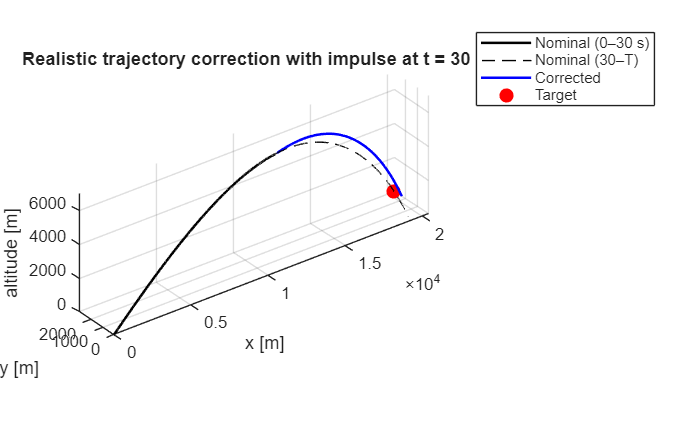

%% --- Nominal trajectory ---

figure; 
idx30 = traj_nom.x <= 30;
X_nom_plot = deval(traj_nom, traj_nom.x(idx30)).';

plot3(X_nom_plot(:,1), ...
      X_nom_plot(:,2), ...
     -X_nom_plot(:,3), 'k', 'LineWidth',1.5); 
hold on

idx30p = traj_nom.x >= 30;
X_nom_post = deval(traj_nom, traj_nom.x(idx30p)).';

plot3(X_nom_post(:,1), ...
      X_nom_post(:,2), ...
     -X_nom_post(:,3), 'k--');

%% --- Perturbed trajectory ---

plot3(X_T_30(:,1), X_T_30(:,2), -X_T_30(:,3),'b','LineWidth',1.5);

% --- Target ---

plot3(X_cible(1),X_cible(2),-X_cible(3),'ro','MarkerSize',8,'MarkerFaceColor','r');

grid on; axis equal
xlabel('x [m]'); ylabel('y [m]'); zlabel('altitude [m]');
legend('Nominal (0–30 s)', 'Nominal (30–T)', ...
       'Corrected', 'Target');
title('Realistic trajectory correction with impulse at t = 30 s');

### Admissible frontiere at max energy

X_front_T_30 = zeros(2, length(theta_vec));

for k = 1:length(theta_vec)

    theta = theta_vec(k);
    u = [cos(theta);sin(theta)];

    c_T_30 = inv(G_T_30(idx,:)'*G_T_30(idx,:)+W)*G_T_30(idx,:)'*r_max_exag*u; % delta_cible = G*c 
    
    if norm(c_T_30) > cmax30
        c_T_30 = cmax30 * c_T_30/norm(c_T_30);
        disp(['Iteración k = ', num2str(k)]);
    end 
    
    delta_x_T_30 = zeros(n,1);
    
    delta_x_T_30(4:6) = c_T_30;
    
    state0_T_30 = x_30_ret + delta_x_T_30;

    [t_T_30, X_T_30, te_T_30, Xe_T_30] = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), [30 200], state0_T_30,options); 
    
    X_front_T_30(:,k) = Xe_T_30(:,idx)';
end

Iteración k = 1
Iteración k = 2
Iteración k = 3
Iteración k = 4
Iteración k = 5
Iteración k = 6
Iteración k = 7
Iteración k = 8
Iteración k = 9
Iteración k = 10
Iteración k = 11
Iteración k = 12
Iteración k = 13
Iteración k = 14
Iteración k = 15
Iteración k = 16
Iteración k = 17
Iteración k = 18
Iteración k = 19
Iteración k = 20
Iteración k = 21
Iteración k = 22
Iteración k = 23
Iteración k = 24
Iteración k = 25
Iteración k = 26
Iteración k = 27
Iteración k = 28
Iteración k = 29
Iteración k = 30
Iteración k = 31
Iteración k = 32
Iteración k = 33
Iteración k = 34
Iteración k = 35
Iteración k = 36
Iteración k = 37
Iteración k = 38
Iteración k = 39
Iteración k = 40
Iteración k = 41
Iteración k = 42
Iteración k = 43
Iteración k = 44
Iteración k = 45
Iteración k = 46
Iteración k = 47
Iteración k = 48
Iteración k = 49
Iteración k = 50
Iteración k = 51
Iteración k = 52
Iteración k = 53
Iteración k = 54
Iteración k = 55
Iteración k = 56
Iteración k = 57
Iteración k = 58
Iteración k = 59
Iterac

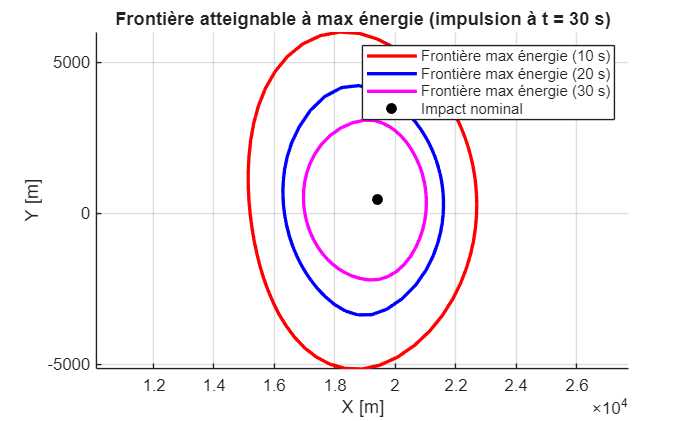

figure; hold on; grid on; axis equal
plot(X_front_T_10(1,:), X_front_T_10(2,:), 'r', 'LineWidth', 2)
plot(X_front_T_20(1,:), X_front_T_20(2,:), 'b', 'LineWidth', 2)
plot(X_front_T_30(1,:), X_front_T_30(2,:), 'm', 'LineWidth', 2)
plot(X_nom(1), X_nom(2), 'ko', 'MarkerFaceColor','k')

xlabel('X [m]')
ylabel('Y [m]')
title("Frontière atteignable à max énergie (impulsion à t = 30 s)")
legend('Frontière max énergie (10 s)','Frontière max énergie (20 s)','Frontière max énergie (30 s)', 'Impact nominal')

### Independent Impulsion at t = 40 s

z_40_0 = deval(traj_nom,40);

x_40_0 = z_40_0(1:n);

v_40_0 = x_40_0(4:6);

v_40_0_nom = norm(v_40_0);

z_40_ret = deval(traj_nom, 40 + retard);

x_40_ret = z_40_ret(1:n);

F_40_0 = reshape(z_40_0(n+1:end),n,n);

F_T_40 = F_T/F_40_0;


G_T_40 = F_T_40(:,4:6); % F(T)*(e4 e5 e6)

c_T_40 = inv(G_T_40(idx,:)'*G_T_40(idx,:)+W)*G_T_40(idx,:)'*delta_cible(idx) % delta_cible = G*c

c_T_40 =  -103.1019
  187.4801
   -3.7388



cmax40 = 0.3*v_40_0_nom

cmax40 = 72.3953


if norm(c_T_40) > cmax40
    c_T_40 = cmax40 * c_T_40/norm(c_T_40);
end 

delta_x_T_40 = zeros(n,1);

delta_x_T_40(4:6) = c_T_40;

state0_T_40 = x_40_ret + delta_x_T_40;

[t_T_40, X_T_40, te_T_40, Xe_T_40] = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), [40 200], state0_T_40,options);  

error_T_40 = X_cible - Xe_T_40'

error_T_40 = 1.0e+03 *

    1.8790
    0.7209
   -0.0000
    0.0172
   -0.0340
   -0.0034
   -0.0008
    0.0004
    0.0002
    0.0006
   -0.0067
    0.0151
   -0.0043


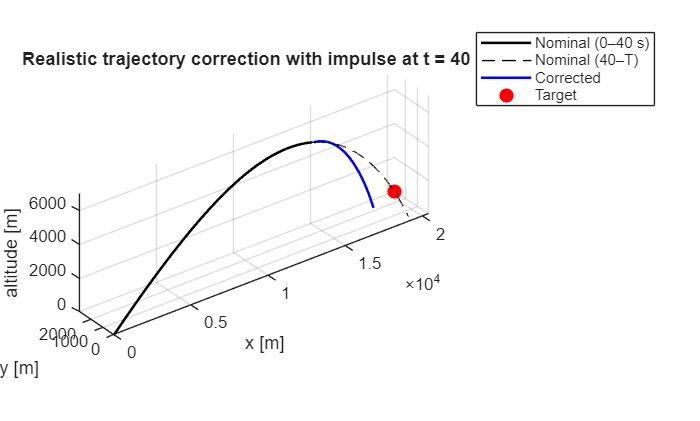

%% --- Nominal trajectory ---

figure; 
idx40 = traj_nom.x <= 40;
X_nom_plot = deval(traj_nom, traj_nom.x(idx40)).';

plot3(X_nom_plot(:,1), ...
      X_nom_plot(:,2), ...
     -X_nom_plot(:,3), 'k', 'LineWidth',1.5); 
hold on

idx40p = traj_nom.x >= 40;
X_nom_post = deval(traj_nom, traj_nom.x(idx40p)).';

plot3(X_nom_post(:,1), ...
      X_nom_post(:,2), ...
     -X_nom_post(:,3), 'k--');

%% --- Perturbed trajectory ---

plot3(X_T_40(:,1), X_T_40(:,2), -X_T_40(:,3),'b','LineWidth',1.5);

% --- Target ---

plot3(X_cible(1),X_cible(2),-X_cible(3),'ro','MarkerSize',8,'MarkerFaceColor','r');

grid on; axis equal
xlabel('x [m]'); ylabel('y [m]'); zlabel('altitude [m]');
legend('Nominal (0–40 s)', 'Nominal (40–T)', ...
       'Corrected', 'Target');
title('Realistic trajectory correction with impulse at t = 40 s');

### Admissible frontiere at max energy

X_front_T_40 = zeros(2, length(theta_vec));

for k = 1:length(theta_vec)

    theta = theta_vec(k);
    u = [cos(theta);sin(theta)];

    c_T_40 = inv(G_T_40(idx,:)'*G_T_40(idx,:)+W)*G_T_40(idx,:)'*r_max_exag*u; % delta_cible = G*c 
    
    if norm(c_T_40) > cmax40
        c_T_40 = cmax40 * c_T_40/norm(c_T_40);
        disp(['Iteración k = ', num2str(k)]);
    end 
    
    delta_x_T_40 = zeros(n,1);
    
    delta_x_T_40(4:6) = c_T_40;
    
    state0_T_40 = x_40_ret + delta_x_T_40;

    [t_T_40, X_T_40, te_T_40, Xe_T_40] = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), [40 200], state0_T_40,options); 
    
    X_front_T_40(:,k) = Xe_T_40(:,idx)';
end

Iteración k = 1
Iteración k = 2
Iteración k = 3
Iteración k = 4
Iteración k = 5
Iteración k = 6
Iteración k = 7
Iteración k = 8
Iteración k = 9
Iteración k = 10
Iteración k = 11
Iteración k = 12
Iteración k = 13
Iteración k = 14
Iteración k = 15
Iteración k = 16
Iteración k = 17
Iteración k = 18
Iteración k = 19
Iteración k = 20
Iteración k = 21
Iteración k = 22
Iteración k = 23
Iteración k = 24
Iteración k = 25
Iteración k = 26
Iteración k = 27
Iteración k = 28
Iteración k = 29
Iteración k = 30
Iteración k = 31
Iteración k = 32
Iteración k = 33
Iteración k = 34
Iteración k = 35
Iteración k = 36
Iteración k = 37
Iteración k = 38
Iteración k = 39
Iteración k = 40
Iteración k = 41
Iteración k = 42
Iteración k = 43
Iteración k = 44
Iteración k = 45
Iteración k = 46
Iteración k = 47
Iteración k = 48
Iteración k = 49
Iteración k = 50
Iteración k = 51
Iteración k = 52
Iteración k = 53
Iteración k = 54
Iteración k = 55
Iteración k = 56
Iteración k = 57
Iteración k = 58
Iteración k = 59
Iterac

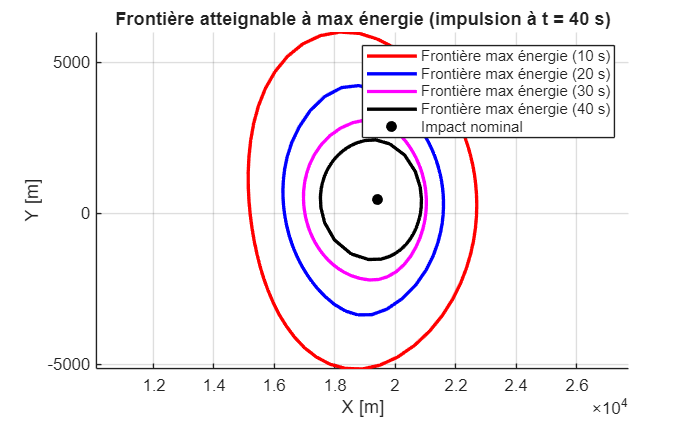

figure; hold on; grid on; axis equal
plot(X_front_T_10(1,:), X_front_T_10(2,:), 'r', 'LineWidth', 2)
plot(X_front_T_20(1,:), X_front_T_20(2,:), 'b', 'LineWidth', 2)
plot(X_front_T_30(1,:), X_front_T_30(2,:), 'm', 'LineWidth', 2)
plot(X_front_T_40(1,:), X_front_T_40(2,:), 'k', 'LineWidth', 2)
plot(X_nom(1), X_nom(2), 'ko', 'MarkerFaceColor','k')

xlabel('X [m]')
ylabel('Y [m]')
title("Frontière atteignable à max énergie (impulsion à t = 40 s)")
legend('Frontière max énergie (10 s)','Frontière max énergie (20 s)','Frontière max énergie (30 s)', ...
    'Frontière max énergie (40 s)','Impact nominal')

### Independent Impulsion at t = 50 s

z_50_0 = deval(traj_nom,50);

x_50_0 = z_50_0(1:n);

v_50_0 = x_50_0(4:6);

v_50_0_nom = norm(v_50_0);

z_50_ret = deval(traj_nom, 50 + retard);

x_50_ret = z_50_ret(1:n);

F_50_0 = reshape(z_50_0(n+1:end),n,n);

F_T_50 = F_T/F_50_0;


G_T_50 = F_T_50(:,4:6); % F(T)*(e4 e5 e6)

c_T_50 = inv(G_T_50(idx,:)'*G_T_50(idx,:)+W)*G_T_50(idx,:)'*delta_cible(idx) % delta_cible = G*c

c_T_50 =   214.9436
   16.5473
   -0.8157



cmax50 = 0.3*v_50_0_nom

cmax50 = 78.0717


if norm(c_T_50) > cmax50
    c_T_50 = cmax50 * c_T_50/norm(c_T_50);
end 

delta_x_T_50 = zeros(n,1);

delta_x_T_50(4:6) = c_T_50;

state0_T_50 = x_50_ret + delta_x_T_50;

[t_T_50, X_T_50, te_T_50, Xe_T_50] = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), [50 200], state0_T_50,options);  

error_T_50 = X_cible - Xe_T_50'

error_T_50 = 1.0e+03 *

   -0.3276
    2.4255
    0.0000
   -0.0302
    0.0030
    0.0147
   -0.0013
    0.0001
    0.0006
   -0.0003
    0.0209
    0.0133
   -0.0112


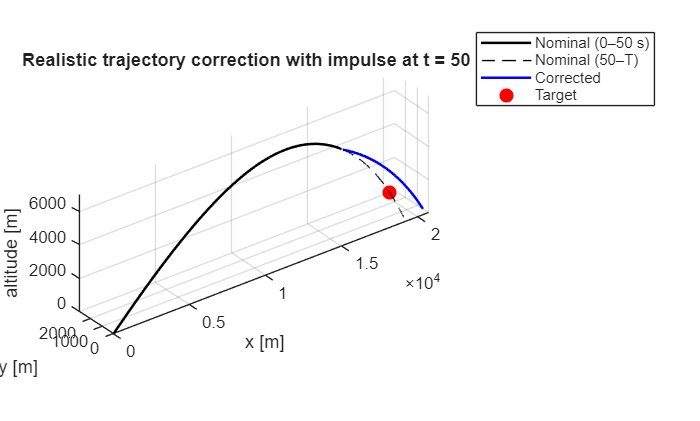

%% --- Nominal trajectory ---

figure; 
idx50 = traj_nom.x <= 50;
X_nom_plot = deval(traj_nom, traj_nom.x(idx50)).';

plot3(X_nom_plot(:,1), ...
      X_nom_plot(:,2), ...
     -X_nom_plot(:,3), 'k', 'LineWidth',1.5); 
hold on

idx50p = traj_nom.x >= 50;
X_nom_post = deval(traj_nom, traj_nom.x(idx50p)).';

plot3(X_nom_post(:,1), ...
      X_nom_post(:,2), ...
     -X_nom_post(:,3), 'k--');

%% --- Perturbed trajectory ---

plot3(X_T_50(:,1), X_T_50(:,2), -X_T_50(:,3),'b','LineWidth',1.5);

% --- Target ---

plot3(X_cible(1),X_cible(2),-X_cible(3),'ro','MarkerSize',8,'MarkerFaceColor','r');

grid on; axis equal
xlabel('x [m]'); ylabel('y [m]'); zlabel('altitude [m]');
legend('Nominal (0–50 s)', 'Nominal (50–T)', ...
       'Corrected', 'Target');
title('Realistic trajectory correction with impulse at t = 50 s');

### Admissible frontiere at max energy

X_front_T_50 = zeros(2, length(theta_vec));

for k = 1:length(theta_vec)

    theta = theta_vec(k);
    u = [cos(theta);sin(theta)];

    c_T_50 = inv(G_T_50(idx,:)'*G_T_50(idx,:)+W)*G_T_50(idx,:)'*r_max_exag*u; % delta_cible = G*c 
    
    if norm(c_T_50) > cmax50
        c_T_50 = cmax50 * c_T_50/norm(c_T_50);
        disp(['Iteración k = ', num2str(k)]);
    end 
    
    delta_x_T_50 = zeros(n,1);
    
    delta_x_T_50(4:6) = c_T_50;
    
    state0_T_50 = x_50_ret + delta_x_T_50;

    [t_T_50, X_T_50, te_T_50, Xe_T_50] = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), [50 200], state0_T_50,options); 
    
    X_front_T_50(:,k) = Xe_T_50(:,idx)';
end

Iteración k = 1
Iteración k = 2
Iteración k = 3
Iteración k = 4
Iteración k = 5
Iteración k = 6
Iteración k = 7
Iteración k = 8
Iteración k = 9
Iteración k = 10
Iteración k = 11
Iteración k = 12
Iteración k = 13
Iteración k = 14
Iteración k = 15
Iteración k = 16
Iteración k = 17
Iteración k = 18
Iteración k = 19
Iteración k = 20
Iteración k = 21
Iteración k = 22
Iteración k = 23
Iteración k = 24
Iteración k = 25
Iteración k = 26
Iteración k = 27
Iteración k = 28
Iteración k = 29
Iteración k = 30
Iteración k = 31
Iteración k = 32
Iteración k = 33
Iteración k = 34
Iteración k = 35
Iteración k = 36
Iteración k = 37
Iteración k = 38
Iteración k = 39
Iteración k = 40
Iteración k = 41
Iteración k = 42
Iteración k = 43
Iteración k = 44
Iteración k = 45
Iteración k = 46
Iteración k = 47
Iteración k = 48
Iteración k = 49
Iteración k = 50
Iteración k = 51
Iteración k = 52
Iteración k = 53
Iteración k = 55
Iteración k = 56
Iteración k = 57
Iteración k = 58
Iteración k = 59
Iteración k = 60


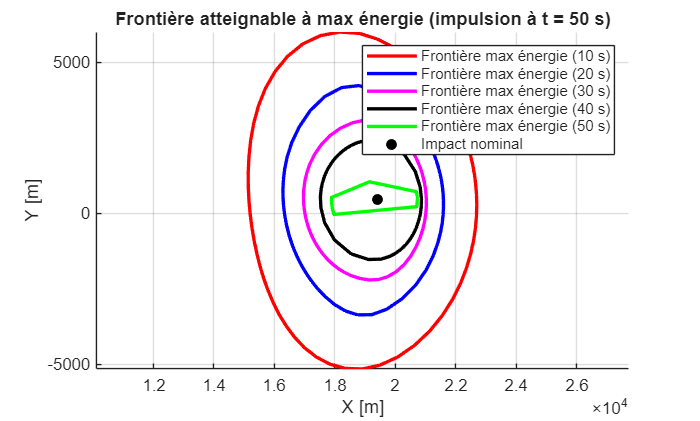

figure; hold on; grid on; axis equal
plot(X_front_T_10(1,:), X_front_T_10(2,:), 'r', 'LineWidth', 2)
plot(X_front_T_20(1,:), X_front_T_20(2,:), 'b', 'LineWidth', 2)
plot(X_front_T_30(1,:), X_front_T_30(2,:), 'm', 'LineWidth', 2)
plot(X_front_T_40(1,:), X_front_T_40(2,:), 'k', 'LineWidth', 2)
plot(X_front_T_50(1,:), X_front_T_50(2,:), 'g', 'LineWidth', 2)
plot(X_nom(1), X_nom(2), 'ko', 'MarkerFaceColor','k')

xlabel('X [m]')
ylabel('Y [m]')
title("Frontière atteignable à max énergie (impulsion à t = 50 s)")
legend('Frontière max énergie (10 s)','Frontière max énergie (20 s)','Frontière max énergie (30 s)', ...
    'Frontière max énergie (40 s)','Frontière max énergie (50 s)','Impact nominal')

### Independent Impulsion at t = 60 s

z_60_0 = deval(traj_nom,60);

x_60_0 = z_60_0(1:n);

v_60_0 = x_60_0(4:6);

v_60_0_nom = norm(v_60_0);

z_60_ret = deval(traj_nom, 60 + retard);

x_60_ret = z_60_ret(1:n);

F_60_0 = reshape(z_60_0(n+1:end),n,n);

F_T_60 = F_T/F_60_0;


G_T_60 = F_T_60(:,4:6); % F(T)*(e4 e5 e6)

c_T_60 = inv(G_T_60(idx,:)'*G_T_60(idx,:)+W)*G_T_60(idx,:)'*delta_cible(idx) % delta_cible = G*c

c_T_60 =   179.0652
   65.5723
   -0.8432



cmax60 = 0.3*v_60_0_nom

cmax60 = 86.1266


if norm(c_T_60) > cmax60
    c_T_60 = cmax60 * c_T_60/norm(c_T_60);
end 

delta_x_T_60 = zeros(n,1);

delta_x_T_60(4:6) = c_T_60;

state0_T_60 = x_60_ret + delta_x_T_60;

[t_T_60, X_T_60, te_T_60, Xe_T_60] = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), [60 200], state0_T_60,options);  

error_T_60 = X_cible - Xe_T_60'

error_T_60 = 1.0e+03 *

    0.0487
    2.1658
    0.0000
   -0.0434
   -0.0117
    0.0181
    0.0000
    0.0003
    0.0013
    0.0001
    0.0172
   -0.0006
   -0.0057


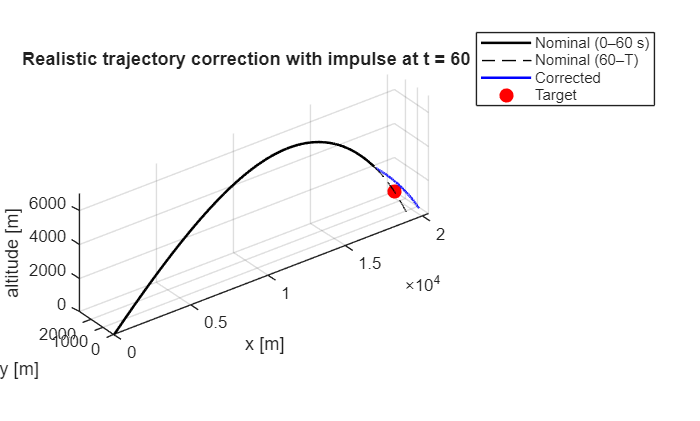

%% --- Nominal trajectory ---

figure; 
idx60 = traj_nom.x <= 60;
X_nom_plot = deval(traj_nom, traj_nom.x(idx60)).';

plot3(X_nom_plot(:,1), ...
      X_nom_plot(:,2), ...
     -X_nom_plot(:,3), 'k', 'LineWidth',1.5); 
hold on

idx60p = traj_nom.x >= 60;
X_nom_post = deval(traj_nom, traj_nom.x(idx60p)).';

plot3(X_nom_post(:,1), ...
      X_nom_post(:,2), ...
     -X_nom_post(:,3), 'k--');

%% --- Perturbed trajectory ---

plot3(X_T_60(:,1), X_T_60(:,2), -X_T_60(:,3),'b','LineWidth',1.5);

% --- Target ---

plot3(X_cible(1),X_cible(2),-X_cible(3),'ro','MarkerSize',8,'MarkerFaceColor','r');

grid on; axis equal
xlabel('x [m]'); ylabel('y [m]'); zlabel('altitude [m]');
legend('Nominal (0–60 s)', 'Nominal (60–T)', ...
       'Corrected', 'Target');
title('Realistic trajectory correction with impulse at t = 60 s');

### Admissible frontiere at max energy

X_front_T_60 = zeros(2, length(theta_vec));

for k = 1:length(theta_vec)

    theta = theta_vec(k);
    u = [cos(theta);sin(theta)];

    c_T_60 = inv(G_T_60(idx,:)'*G_T_60(idx,:)+W)*G_T_60(idx,:)'*r_max_exag*u; % delta_cible = G*c 
    
    if norm(c_T_60) > cmax60
        c_T_60 = cmax60 * c_T_60/norm(c_T_60);
        disp(['Iteración k = ', num2str(k)]);
    end 
    
    delta_x_T_60 = zeros(n,1);
    
    delta_x_T_60(4:6) = c_T_60;
    
    state0_T_60 = x_60_ret + delta_x_T_60;

    [t_T_60, X_T_60, te_T_60, Xe_T_60] = ode45(@(t,x) proj_dynamics(t,x, D, S, M, Il, It, ...
                                   rho0, g0, a0, Rearth, Mach_table, CD_table, CL_table, ...
                                   Cmagf_table, Cmagm_table, CMq_table, CMa_table, ...
                                   Cspin_table, interpCoeff), [60 200], state0_T_60,options); 
    
    X_front_T_60(:,k) = Xe_T_60(:,idx)';
end

Iteración k = 1
Iteración k = 2
Iteración k = 3
Iteración k = 4
Iteración k = 5
Iteración k = 6
Iteración k = 7
Iteración k = 8
Iteración k = 9
Iteración k = 10
Iteración k = 11
Iteración k = 12
Iteración k = 13
Iteración k = 14
Iteración k = 15
Iteración k = 16
Iteración k = 17
Iteración k = 18
Iteración k = 19
Iteración k = 20
Iteración k = 21
Iteración k = 22
Iteración k = 23
Iteración k = 24
Iteración k = 25
Iteración k = 26
Iteración k = 27
Iteración k = 28
Iteración k = 29
Iteración k = 30
Iteración k = 31
Iteración k = 32
Iteración k = 33
Iteración k = 34
Iteración k = 35
Iteración k = 36
Iteración k = 37
Iteración k = 38
Iteración k = 39
Iteración k = 40
Iteración k = 41
Iteración k = 42
Iteración k = 43
Iteración k = 44
Iteración k = 45
Iteración k = 46
Iteración k = 47
Iteración k = 48
Iteración k = 49
Iteración k = 50
Iteración k = 51
Iteración k = 52
Iteración k = 53
Iteración k = 55
Iteración k = 56
Iteración k = 57
Iteración k = 58
Iteración k = 59
Iteración k = 60


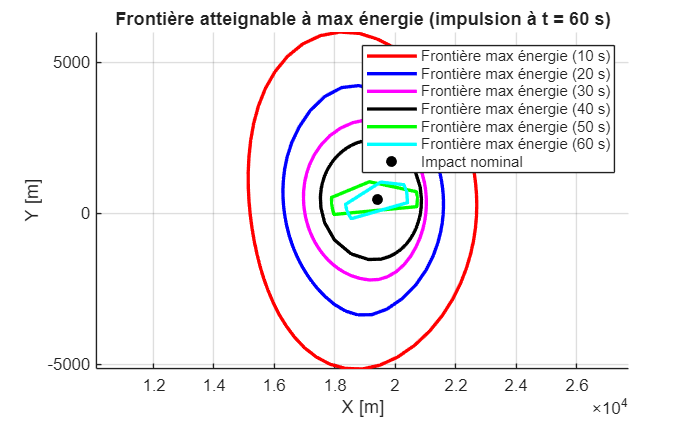

figure; hold on; grid on; axis equal
plot(X_front_T_10(1,:), X_front_T_10(2,:), 'r', 'LineWidth', 2)
plot(X_front_T_20(1,:), X_front_T_20(2,:), 'b', 'LineWidth', 2)
plot(X_front_T_30(1,:), X_front_T_30(2,:), 'm', 'LineWidth', 2)
plot(X_front_T_40(1,:), X_front_T_40(2,:), 'k', 'LineWidth', 2)
plot(X_front_T_50(1,:), X_front_T_50(2,:), 'g', 'LineWidth', 2)
plot(X_front_T_60(1,:), X_front_T_60(2,:), 'c', 'LineWidth', 2)
plot(X_nom(1), X_nom(2), 'ko', 'MarkerFaceColor','k')

xlabel('X [m]')
ylabel('Y [m]')
title("Frontière atteignable à max énergie (impulsion à t = 60 s)")
legend('Frontière max énergie (10 s)','Frontière max énergie (20 s)','Frontière max énergie (30 s)', ...
    'Frontière max énergie (40 s)','Frontière max énergie (50 s)','Frontière max énergie (60 s)','Impact nominal')

### 2 Impulsions at t = 10 s and t = 60 s

### Admissible frontiere at max energy

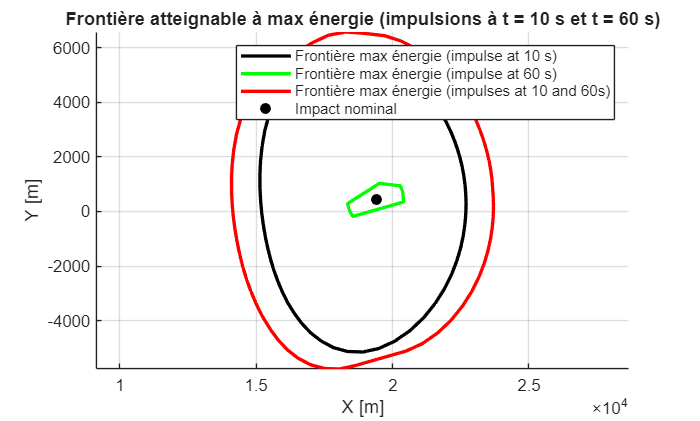

delta_front_T_60 = zeros(2, length(theta_vec));
X_front_T_60_10_temp = zeros(2, length(theta_vec));
P = [];

for k = 1:length(theta_vec)
    delta_front_T_60(:,k) = X_front_T_60(:,k) - X_nom(idx);
end

figure; hold on; grid on; axis equal

for k = 1:length(theta_vec)
    X_front_T_10_theta = X_front_T_10(:,k);

    for i = 1:length(theta_vec)
        X_front_T_60_10_temp(:,i) = X_front_T_10_theta + delta_front_T_60(:,i);
    end

    P = [P, X_front_T_60_10_temp];

    %plot(X_front_T_60_10_temp(1,:),X_front_T_60_10_temp(2,:),'g','LineWidth', 2);
end

K = convhull(P(1,:)', P(2,:)');

X_front_T_60_10 = P(:,K);

h1 = plot(X_front_T_10(1,:), X_front_T_10(2,:), 'k', 'LineWidth', 2);
h2 = plot(X_front_T_60(1,:), X_front_T_60(2,:), 'g', 'LineWidth', 2);
h3 = plot(X_front_T_60_10(1,:), X_front_T_60_10(2,:), 'r', 'LineWidth', 2);
h4 = plot(X_nom(1), X_nom(2), 'ko', 'MarkerFaceColor','k');

%plot([0 X_nom(1)],[0 X_nom(2)],'-o');

xlabel('X [m]')
ylabel('Y [m]')
title("Frontière atteignable à max énergie (impulsions à t = 10 s et t = 60 s)")
legend([h1 h2 h3 h4],'Frontière max énergie (impulse at 10 s)', 'Frontière max énergie (impulse at 60 s)',...
    'Frontière max énergie (impulses at 10 and 60s)','Impact nominal')

### 2 Impulsions at t = 10 s and t = 50 s

### Admissible frontiere at max energy

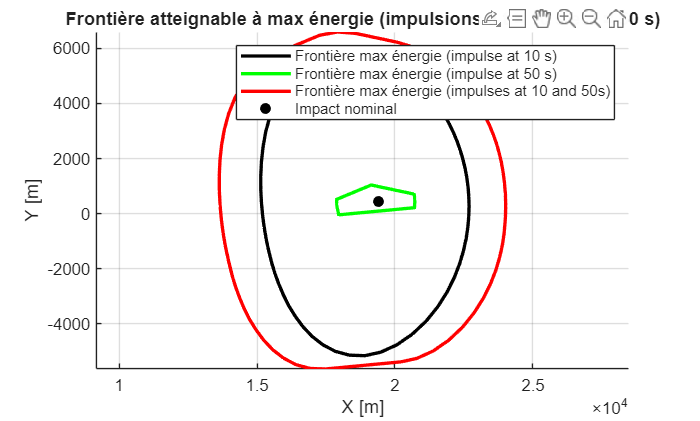

delta_front_T_50 = zeros(2, length(theta_vec));
X_front_T_50_10_temp = zeros(2, length(theta_vec));
P = [];

for k = 1:length(theta_vec)
    delta_front_T_50(:,k) = X_front_T_50(:,k) - X_nom(idx);
end

figure; hold on; grid on; axis equal

for k = 1:length(theta_vec)
    X_front_T_10_theta = X_front_T_10(:,k);

    for i = 1:length(theta_vec)
        X_front_T_50_10_temp(:,i) = X_front_T_10_theta + delta_front_T_50(:,i);
    end

    P = [P, X_front_T_50_10_temp];

    %plot(X_front_T_50_10_temp(1,:),X_front_T_50_10_temp(2,:),'b','LineWidth', 2);
end

K = convhull(P(1,:)', P(2,:)');

X_front_T_50_10 = P(:,K);

plot(X_front_T_10(1,:), X_front_T_10(2,:), 'k', 'LineWidth', 2)
plot(X_front_T_50(1,:), X_front_T_50(2,:), 'g', 'LineWidth', 2)
plot(X_front_T_50_10(1,:), X_front_T_50_10(2,:), 'r', 'LineWidth', 2)
plot(X_nom(1), X_nom(2), 'ko', 'MarkerFaceColor','k')

%plot([0 X_nom(1)],[0 X_nom(2)],'-o');

xlabel('X [m]')
ylabel('Y [m]')
title("Frontière atteignable à max énergie (impulsions à t = 10 s et t = 50 s)")
legend('Frontière max énergie (impulse at 10 s)', 'Frontière max énergie (impulse at 50 s)',...
    'Frontière max énergie (impulses at 10 and 50s)','Impact nominal')

### 2 Impulsions at t = 10 s and t = 40 s

### Admissible frontiere at max energy

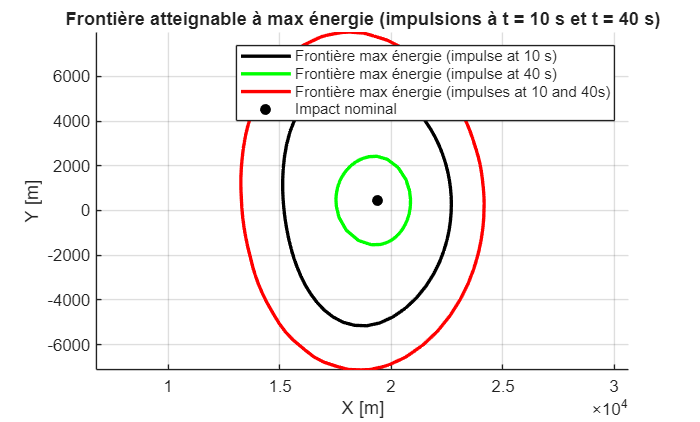

delta_front_T_40 = zeros(2, length(theta_vec));
X_front_T_40_10_temp = zeros(2, length(theta_vec));
P = [];

for k = 1:length(theta_vec)
    delta_front_T_40(:,k) = X_front_T_40(:,k) - X_nom(idx);
end

figure; hold on; grid on; axis equal

for k = 1:length(theta_vec)
    X_front_T_10_theta = X_front_T_10(:,k);

    for i = 1:length(theta_vec)
        X_front_T_40_10_temp(:,i) = X_front_T_10_theta + delta_front_T_40(:,i);
    end

    P = [P, X_front_T_40_10_temp];

    %plot(X_front_T_40_10_temp(1,:),X_front_T_40_10_temp(2,:),'b','LineWidth', 2);
end

K = convhull(P(1,:)', P(2,:)');

X_front_T_40_10 = P(:,K);

plot(X_front_T_10(1,:), X_front_T_10(2,:), 'k', 'LineWidth', 2)
plot(X_front_T_40(1,:), X_front_T_40(2,:), 'g', 'LineWidth', 2)
plot(X_front_T_40_10(1,:), X_front_T_40_10(2,:), 'r', 'LineWidth', 2)
plot(X_nom(1), X_nom(2), 'ko', 'MarkerFaceColor','k')

%plot([0 X_nom(1)],[0 X_nom(2)],'-o');

xlabel('X [m]')
ylabel('Y [m]')
title("Frontière atteignable à max énergie (impulsions à t = 10 s et t = 40 s)")
legend('Frontière max énergie (impulse at 10 s)', 'Frontière max énergie (impulse at 40 s)',...
    'Frontière max énergie (impulses at 10 and 40s)','Impact nominal')

### 2 Impulsions at t = 10 s and t = 30 s

### Admissible frontiere at max energy

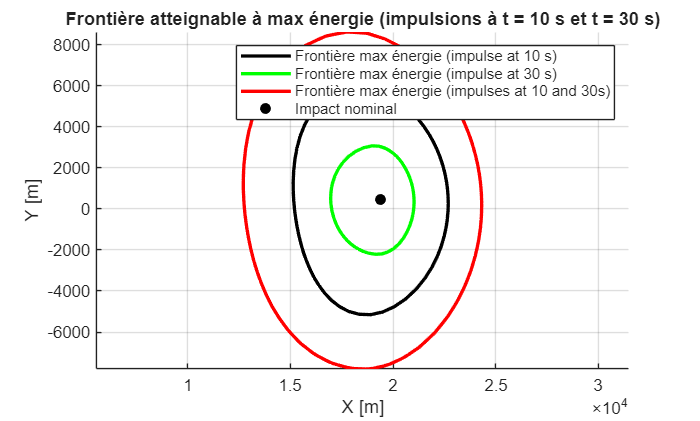

delta_front_T_30 = zeros(2, length(theta_vec));
X_front_T_30_10_temp = zeros(2, length(theta_vec));
P = [];

for k = 1:length(theta_vec)
    delta_front_T_30(:,k) = X_front_T_30(:,k) - X_nom(idx);
end

figure; hold on; grid on; axis equal

for k = 1:length(theta_vec)
    X_front_T_10_theta = X_front_T_10(:,k);

    for i = 1:length(theta_vec)
        X_front_T_30_10_temp(:,i) = X_front_T_10_theta + delta_front_T_30(:,i);
    end

    P = [P, X_front_T_30_10_temp];

    %plot(X_front_T_30_10_temp(1,:),X_front_T_30_10_temp(2,:),'b','LineWidth', 2);
end

K = convhull(P(1,:)', P(2,:)');

X_front_T_30_10 = P(:,K);

plot(X_front_T_10(1,:), X_front_T_10(2,:), 'k', 'LineWidth', 2)
plot(X_front_T_30(1,:), X_front_T_30(2,:), 'g', 'LineWidth', 2)
plot(X_front_T_30_10(1,:), X_front_T_30_10(2,:), 'r', 'LineWidth', 2)
plot(X_nom(1), X_nom(2), 'ko', 'MarkerFaceColor','k')

%plot([0 X_nom(1)],[0 X_nom(2)],'-o');

xlabel('X [m]')
ylabel('Y [m]')
title("Frontière atteignable à max énergie (impulsions à t = 10 s et t = 30 s)")
legend('Frontière max énergie (impulse at 10 s)', 'Frontière max énergie (impulse at 30 s)',...
    'Frontière max énergie (impulses at 10 and 30s)','Impact nominal')

### 2 Impulsions at t = 10 s and t = 20 s

### Admissible frontiere at max energy

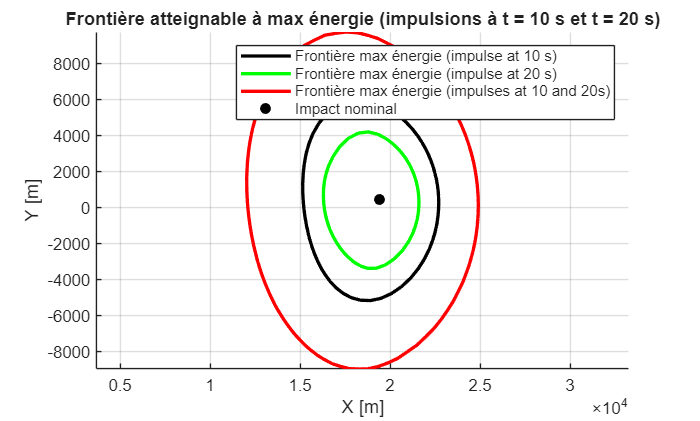

delta_front_T_20 = zeros(2, length(theta_vec));
X_front_T_20_10_temp = zeros(2, length(theta_vec));
P = [];

for k = 1:length(theta_vec)
    delta_front_T_20(:,k) = X_front_T_20(:,k) - X_nom(idx);
end

figure; hold on; grid on; axis equal

for k = 1:length(theta_vec)
    X_front_T_10_theta = X_front_T_10(:,k);

    for i = 1:length(theta_vec)
        X_front_T_20_10_temp(:,i) = X_front_T_10_theta + delta_front_T_20(:,i);
    end

    P = [P, X_front_T_20_10_temp];

    %plot(X_front_T_20_10_temp(1,:),X_front_T_20_10_temp(2,:),'b','LineWidth', 2);
end

K = convhull(P(1,:)', P(2,:)');

X_front_T_20_10 = P(:,K);

plot(X_front_T_10(1,:), X_front_T_10(2,:), 'k', 'LineWidth', 2)
plot(X_front_T_20(1,:), X_front_T_20(2,:), 'g', 'LineWidth', 2)
plot(X_front_T_20_10(1,:), X_front_T_20_10(2,:), 'r', 'LineWidth', 2)
plot(X_nom(1), X_nom(2), 'ko', 'MarkerFaceColor','k')

%plot([0 X_nom(1)],[0 X_nom(2)],'-o');

xlabel('X [m]')
ylabel('Y [m]')
title("Frontière atteignable à max énergie (impulsions à t = 10 s et t = 20 s)")
legend('Frontière max énergie (impulse at 10 s)', 'Frontière max énergie (impulse at 20 s)',...
    'Frontière max énergie (impulses at 10 and 20s)','Impact nominal')